# **LABORATIONSUPPGIFTER I TSDT18/84 SIGNALER & SYSTEM**

# **LABORATION 3**

# 4. Tidskontinuerliga frekvensselektiva filter

Klicka på [STARTUP] nedan för att initiera Kretslab, innan du börjar med uppgifterna!

 
startup;

**OBS:** Laboration 3 och 4 är **mer tidskrävande** än tidigare laborationer, så påbörja gärna arbetet med uppgifterna snarast efter att du är färdig med redovisningen av laboration 2! Det är även lämpligt att påbörja laboration 3 innan kursmomentet frekvensselektiva filter tas upp på en föreläsning (den andra laplacetransformrelaterade föreläsningen), vilket innebär att du behöver **gå igenom motsvarande kursmaterial i kursbokens kapitel 4.10 själv innan du påbörjar Laboration 3**! 

*Om du vill (ej nödvändigt, men rekommenderas), så kan du även titta igenom följande material:*

- [**Föreläsningsmaterialet från 2019**](https://www.cvl.isy.liu.se/education/undergraduate/TSDT18/forelasningar/Intro.Frekv.sel.Filter.pdf)* om relationen mellan *$H\left(s\right)$* och *$H\left(\omega \right)$* via pol-nollställevektorer samt om frekvensselektiva filter.*

- *Kursbokens Matlabsession 4 "Continuous-time filters", efter kapitel 4.12 (sid. 468-478). Där finns ett antal funktionsanrop som illustrerar/demonstrerar butterworthfilter och chebyshevfilter. Om du i Matlabs kommandofönster anropar matlabskriptet *`MS4`* så kan du stega dig igenom (tryck på mellanslagstangenten efter varje paus) de exempel som visas i Matlabsession 4, samtidigt som du gärna följer med i motsvarande delar i kursboken. Detta ger en del grundläggande förståelse för kommande uppgifter. *

**I denna laboration kommer du bland annat att designa frekvensselektiva filter (LTI-system) genom att placera ut poler och nollställen hos systemfunktionen **$H\left(s\right)$** på lämpliga platser i *****s*****-planet**. Hur LTI-systemens tids- och frekvensegenskaper beror på placeringen av polerna och nollställena är mycket centralt.

## Uppgift 4.1 – Egenskaper hos två enkla LTI-system

Två LTI-system har impulssvaren $h_1 \left(t\right)=e^{-3t} u\left(t\right)$ respektive $h_2 \left(t\right)=e^{-3t} \sin \left(2\pi 5t\right)u\left(t\right)$ och motsvarande systemfunktioner $H_1 \left(s\right)$ respektive $H_2 \left(s\right)$.

Du skall nedan undersöka hur dessa två LTI-systems tids- och frekvensegenskaper ändras då de motsvarande systemfunktionernas poler flyttas i *s*-planet.

### Uppgift 4.1a

Ange/bestäm *systemfunktionerna* (hämtas lämpligen från från en transformtabell)! Ange även systemfunktionernas *konvergensområde*!

*Klicka precis till höger om "="-tecknen nedan för att aktivera "ekvationsläget", där du kan skriva in ekvationer m.h.a. symbolerna som då kommer fram längst upp i Matlabfönstret.*

☆  ${\mathit{\mathbf{H}}}_1 \left(\mathit{\mathbf{s}}\right)=\frac{1}{s+3}\;\;\;$S.27 formel 11

☆  ${\mathit{\mathbf{H}}}_2 \left(\mathit{\mathbf{s}}\right)=\frac{100\pi^2 }{\left({\left(s+3\right)}^2 +100\pi^2 \right)}\;\;\;$S.28 formel 21

Vilken kausalitetsegenskap gäller för de två LTI-systemen? Motivera!

☆  **Svar:**  Konvergensområdet  är Re{S} > -3 för både H1 och H2. Båda systemfunktionerna är kausala ty de är stabila.

### Uppgift 4.1b

Här ska du undersöka hur amplitudkaraktäristiken $\left|H_1 \left(f\right)\right|$ och impulssvaret $h_1 \left(t\right)$ ändras när polen i $H_1 \left(s\right)$ flyttas längs den reella axeln i *s*-planet. Du ändrar polens position (realdel) mellan $s=-10$ och $s=-0\ldotp 1$ med hjälp av det översta reglaget nedan och du markerar i rutorna vilka grafer, utöver pol-nollställediagrammet, som ska ritas (amplitudkaraktäristik $\left|H_1 \left(f\right)\right|$, faskaraktäristik ${\arg \;H}_1 \left(f\right)$, respektive impulssvaret $h_1 \left(t\right)$).

Vid valet att visa $\left|H_1 \left(s\right)\right|$ så ritas en 3D-plot av $\left|H_1 \left(s\right)\right|$ i ett kvadratiskt område i vänstra halvplanet, där den röda linjen längs imaginära axeln är $\left|H_1 \left(\omega \right)\right|$. Notera att *funktionen* $\left|H_1 \left(s\right)\right|$ även ritas utanför konvergensområdet, men det är bara i konvergensområdet som vi har vår *laplacetransform*! 

(*Reflektera över detta och **var** konvergensområdet är i detta fall – se Uppgift 4.1a*).

Med de två övriga reglagen bestämmer du hur långt upp i frekvens respektive tid som frekvenskaraktäristiken respektive impulssvaret ska ritas. Du kan även, vid behov, själv zooma in i graferna*.*

- När polen flyttas bör du särskilt fokusera på förändringar i hur snabbt amplitudkaraktäristiken och impulssvaret går mot noll samt hur motsvarande bandbredd respektive storlek/funktionsvärden ändras. 

- Då $\left|H_1 \left(s\right)\right|$ ritas, så erhåller du även ett *fristående fönster* med samma graf. Där kan du **rotera grafen** för att studera den närmare. Gör det! Symbolen   ovanför grafen är då markerad. Ibland kan det även vara lämpligt att zooma in   och flytta grafen   för att studera den närmare.

- *Vi bryr oss inte så mycket om faskaraktäristiken just nu, den finns främst med för den som är intresserad.*

Realdel = -9.6;

 
KRETSLAB ÄR INITIERAD!
(Ett antal globala variabler är definierade)
 
För den intresserade (men behövs ej för att lösa uppgifterna):
Om du skriver 'kretslab' i kommandofönstret så öppnas ett
hjälpfönster där tollboxens funktioner är beskrivna.
 


fmax = 24;
tmax = 18;

Amplidudkar = true;
Faskar = false;
plot3D = true;
Impulssvar = true;
uppgift411

Vad händer när polen hos $H_1 \left(s\right)$ förskjuts längs reella axeln? *Förklara, i ditt svar, relationen mellan graferna! *Reflektera t.ex. över

- *Hur impulssvaret påverkas av polens läge.*

- *Frekvensfunktionens beroende av systemfunktionen och des pol(er). Kom i håg att fouriertransformen (i normalfallet) är lika med laplacetransformen längs imaginära axeln i s-planet.*

☆  **Svar:**  

Vi ser att då realdelen minskar ökar bredden på impulssvaret. Dvs att impulssvaret sjunker långsammare (kurvan blir mer utdragen). Vi ser också att amplitudkaraktäristiken vid polen är $\frac{1}{|a|}$

[*Lämna reglagen i ett läge som visar ett system som du tycker är lämpligt att visa vid redovisningen*]

### Uppgift 4.1c

Nu ska du i stället undersöka hur amplitudkaraktäristiken $\left|H_2 \left(f\right)\right|$ och impulssvaret $h_2 \left(t\right)$ ändras när de två polerna i $H_2 \left(s\right)$ flyttas – å ena sidan parallellt med den reella axeln och å andra sidan parallellt med den imaginära axeln i *s*-planet. Du ändrar den övre polens position (realdel respektive imaginärdel) med hjälp av de två reglagen nedan och liksom i Uppgift 4.1b markerar du i rutorna vilka grafer, utöver pol-nollställediagrammet, som du vill ska ritas.

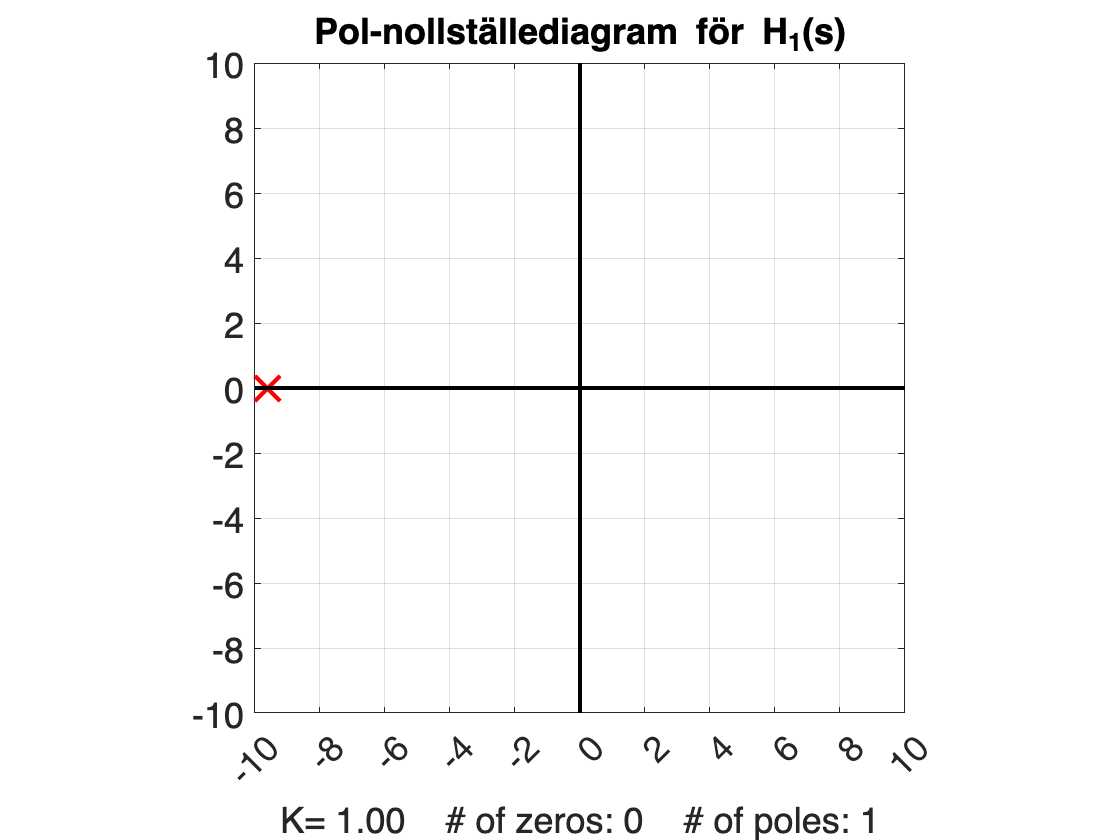

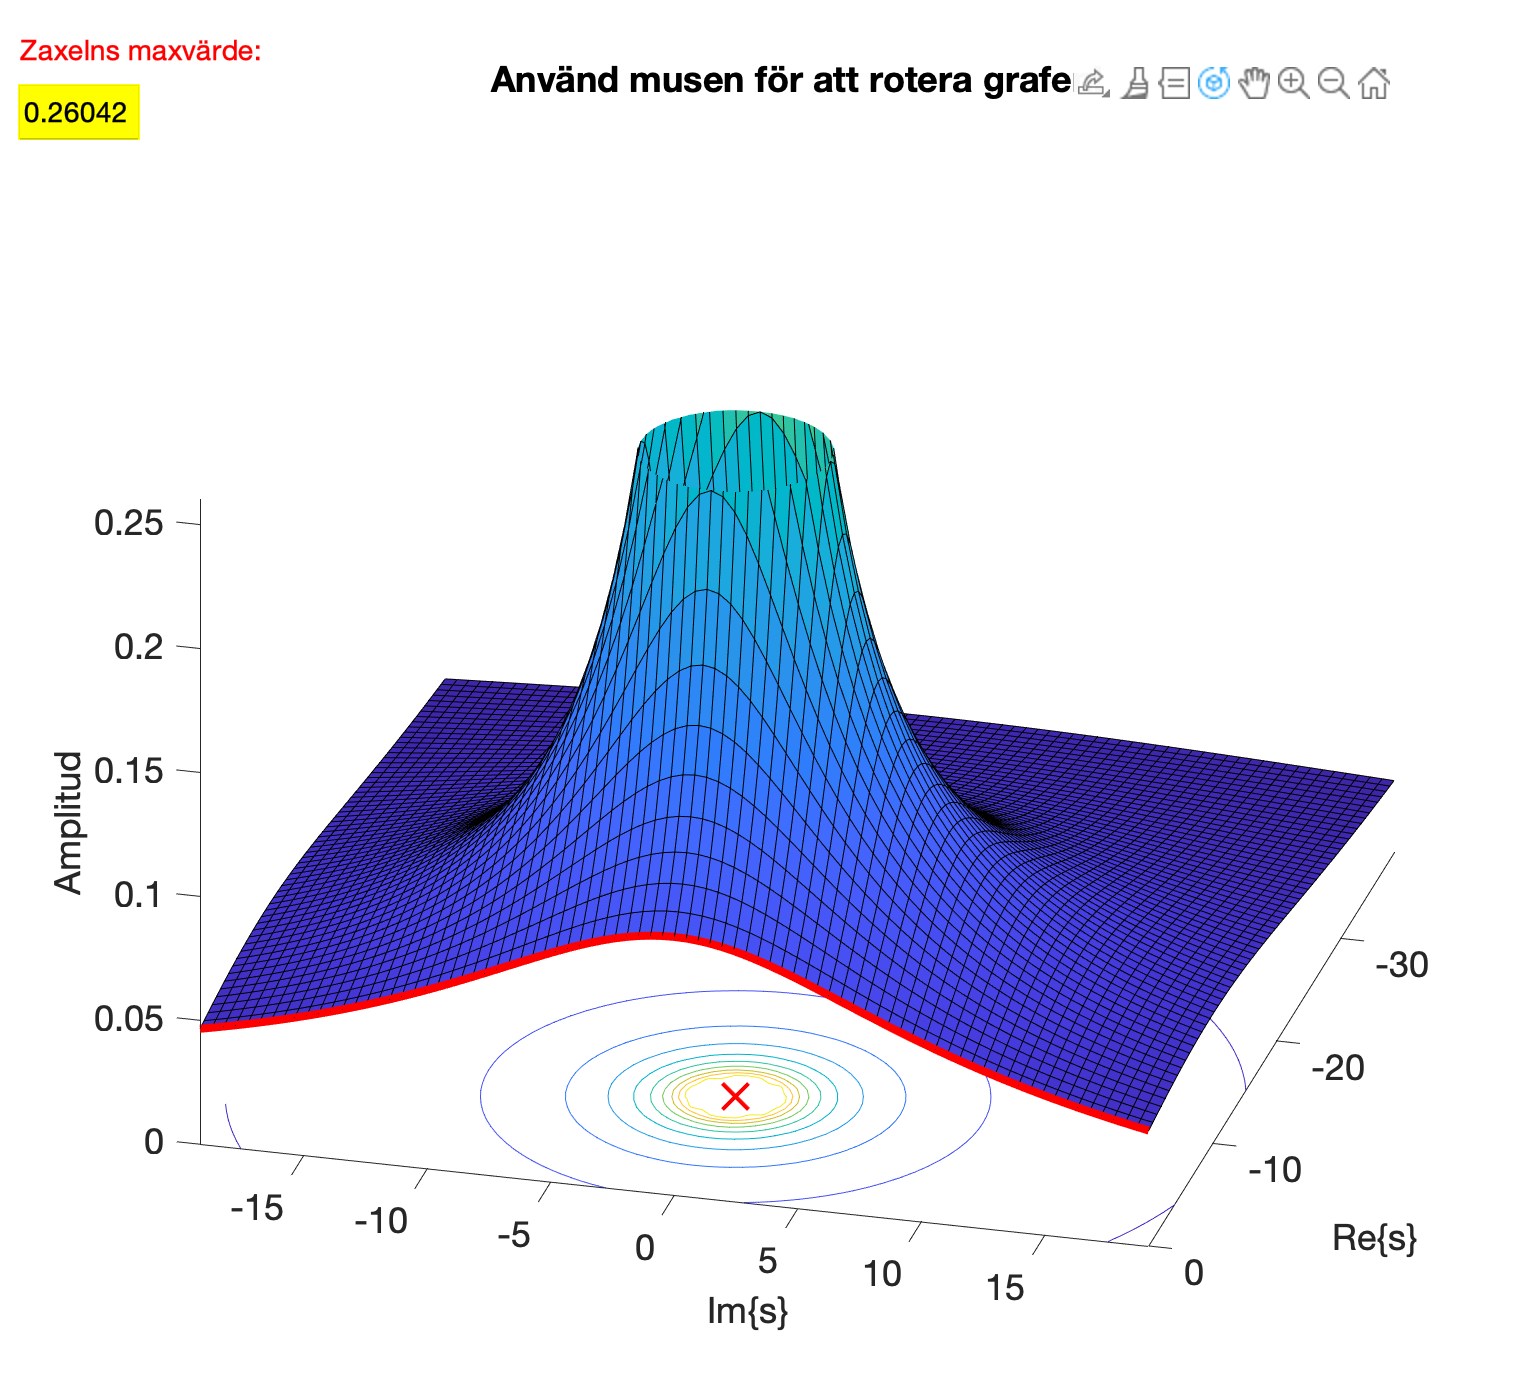

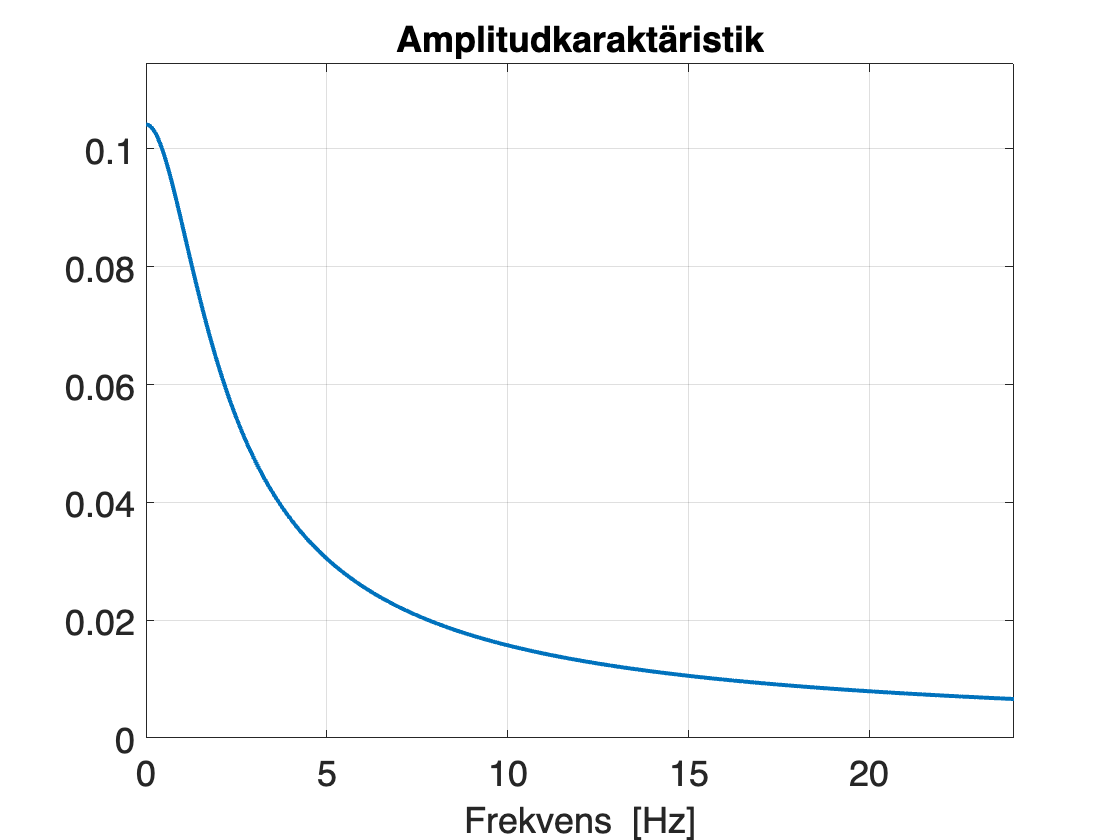

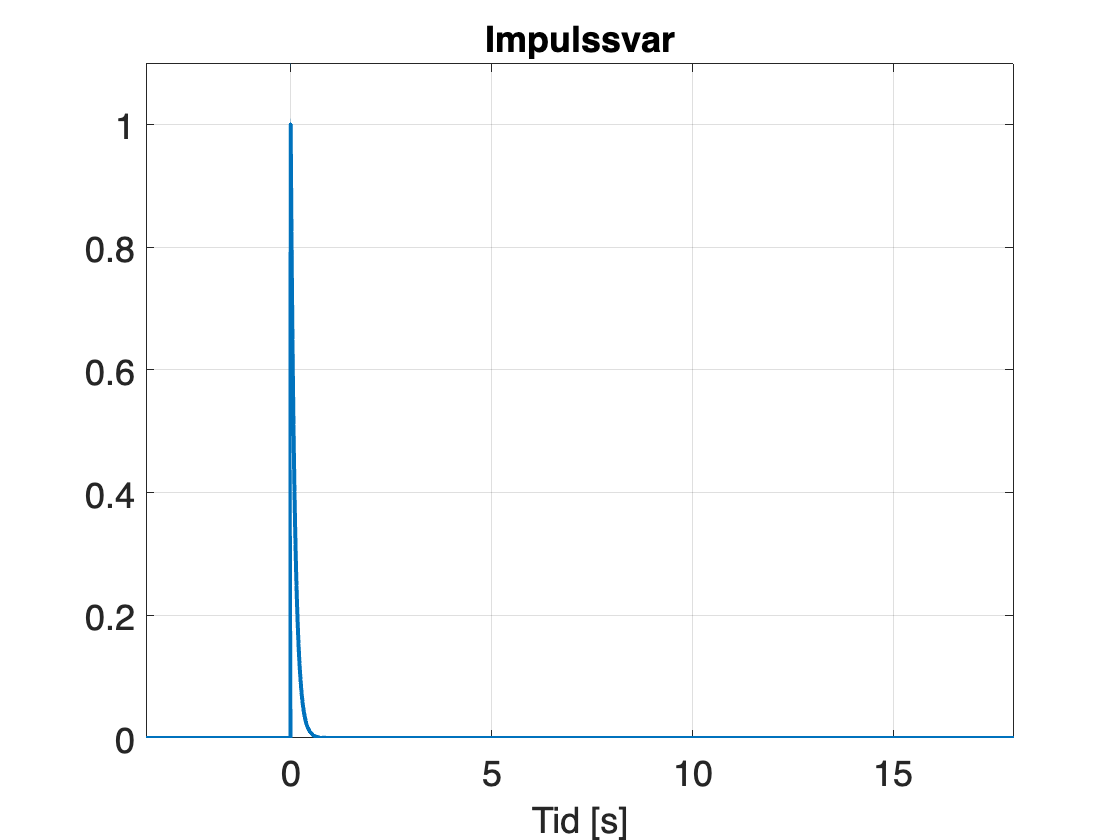

Realdel = -4;
Imagdel = 10;
fmax = 40; 
tmax = 2;

Amplidudkar = true;
Faskar = false;
plot3D = true;
Impulssvar = true;
uppgift412

Vad händer när polerna hos $H_2 \left(s\right)$flyttas 

- *parallellt med reella axeln* respektive 

- *parallellt med imaginära axeln*? 

*Förklara relationen mellan graferna, utgående från samma principer som du gjorde för * $H_1 \left(s\right)$ ovan*!*

☆  **Svar:**  

Vi ser att amplituden på impulssvaret minskar då Re{S} går mot minus oändligheten. Vidare syns det att impulssvaret minskar långsammare (svängningarna blir fler, men minskar i utslag) då Re{S} går mot noll.

När Im{S} blir större ökar frekvensen hos impulssvaret. Amplituden ändras dock inte ty sinus pendlar mellan 0 och 1.

[*Lämna reglagen i ett läge som visar ett system som du tycker är lämpligt att visa vid redovisningen*]

## Uppgift 4.2 – HP-filter av ordning 2

Under resten av Laboration 3 och under Laboration 4 kommer du att använda ett verktyg (en Kretslabfunktion) vid namn `pzchange`, med vilken man manuellt kan justera poler och nollställen hos systemfunktionen $H\left(s\right)$ och samtidigt se hur motsvarande amplitudkaraktäristik $\left|H\left(\omega \right)\right|$ och faskaraktäristik $\arg \;H\left(\omega \right)$ ändras. (*Detsamma gäller naturligtvis för en signal med laplacetransform *$X\left(s\right)$* och motsvarande amplitudspektrum *$\left|X\left(\omega \right)\right|$* och fasspektrum *$\arg \;X\left(\omega \right)$). 

Speciellt kommer du att använda `pzchange `för att **skapa olika frekvensselektiva filter** utgående från olika filterkrav.

### Uppgift 4.2a

Innan du börjar använda `pzchange`, så behöver du veta hur verktyget fungerar och vilka begränsningar som finns, t.ex. att de laplacetransformer och *z*-transformer (i Laboration 4) som skapas och manipuleras antas vara *enkelsidiga*, samt att `pzchange` bara kan anropas/användas för en transform i taget. 

**Se därför till att du sparar den transform du jobbar med i **`pzchange`** innan du startar en ny **`pzchange`**! **Det gör du genom att klicka på knapparna **[Spara HP-filtret]**,  **[Spara LP-filtret]**  och  **[Spara BP-filtret]**  i de tre motsvarande uppgifterna nedan.

- [**Se följande YouTube-video**](https://youtu.be/esrVNnXNMJk) (<– klicka på länken!), som steg för steg visar hur `pzchange` används – det kommer underlätta ditt arbete mycket! 

- Det finns även ett kompletterande [**hjälpdokument för **`pzchange`](https://www.cvl.isy.liu.se/education/undergraduate/TSDT18/laborationer/pzchangeREADME.pdf) (<– klicka på länken!) som beskriver de vanligaste möjligheterna och begränsningarna.

### Uppgift 4.2b

Nedan ska du använda `pzchange` för att skapa en systemfunktionen $H_{\textrm{HP}} \left(s\right)$ till ett LTI-system. `pzchange` utgår från att laplacetransformen du jobbar med har ett *högersidigt konvergensområde*, dvs. att det motsvarande LTI-systemet är *kausalt*. Du ska placera och manuellt justera systemfunktionens poler och nollställen positioner i *s*-planet så att du, om det är möjligt, uppfyller följande filterkrav:

- Systemfunktionen ska ha **två poler **och **två nollställen**.

- Systemet utgör ett **amplitudnormerat **och **stabilt högpassfilter**.

- HP-filtrets **3 dB-gränsfrekvens **är** 30 Hz**.

- 
$$\lim_{\mathit{\mathbf{f}}\to 0} \left|{\mathit{\mathbf{H}}}_{\textrm{HP}} \left(\mathit{\mathbf{f}}\right)\right|=0\ldotp$$


**Tips och vägledande information – viktig information:**

- Huvudtanken med uppgiften är att du ska få en *känsla och förståelse* för hur poler och nollställen samverkar för att ge önskad amplitudkaraktäristik. **Testa** därför först att flytta runt polerna och nollställena lite godtyckligt, för att se hur systemets frekvensegenskaper ändras. Här har du nytta av dina erfarenheter och slutsatser från Uppgift 4.1för att förstå vad som händer och varför! 

- Notera att när du ändrar en komplexkonjugerad pol/nollställe så ändras den komplexkonjugerade motsvarigheten automatiskt.

- Jobba inte för länge med att få till en 3 dB-gränsfrekvens på *exakt* 30 Hz, det är den *principiella förståelsen* som är viktigast här. Det är OK med en gränsfrekvens mellan 29.5 och 30.5 Hz.

- I pzchange-menyn "Normera" kan du toggla inställningen till "PÅ", så att `pzchange `automatiskt justerar nivåkonstanten så du erhåller ett amplitudnormerat filter (maxamplituden = 1).

- Du behöver utgå från en lämplig *princip* för var ungefär systemfunktionernas poler och nollställen bör placeras för att erhålla önskad amplitudkaraktäristik. Som det står i början av avsnitt 4 – gå gärna igenom relaterat avsnitt i kursbokens kapitel 4.10 och motsvarande föreläsningsmaterial om frekvensselektiva filter. Se även inledningen av formelsamlingens kapitel 4.3, sidan 12.

- Eftersom systemet skall vara *stabilt*, kan du inte placera polerna var som helst...

Om du redan har skapat och sparat ett högpassfilter (HP-filter), så kan du ladda in det i Matlab genom att klicka på knappen [Ladda HP-filtret]:

 
alt=1; uppgift42

Klicka på knappen [Starta pzchange] nedan för att starta `pzchange` med ditt skapade/sparade HP-filter. Om det är första gången du gör detta, så startar `pzchange` med $H_{\textrm{HP}} \left(s\right)=1$. Två `pzchange`-fönster kommer att öppnas/visas – en version i skript-dokumentet och en version i ett fristående `pzchange`-fönster. Det är i det *fristående *fönstret du ska jobba med `pzchange`.

 
alt=2; uppgift42

När du i `pzchange `är klar med ditt HP-filter, så klickar du på knappen [Spara HP-filtret] nedan. Då sparas din systemfunktion som variabeln H_HP i datafilen Uppgift42.mat.

***OBS****: Gör detta ****innan**** du startar *`pzchange`* igen, för *`pzchange`* kan bara hantera ****en transform i taget****!! (Transformen lagras som den globala variabeln TRMF.)*

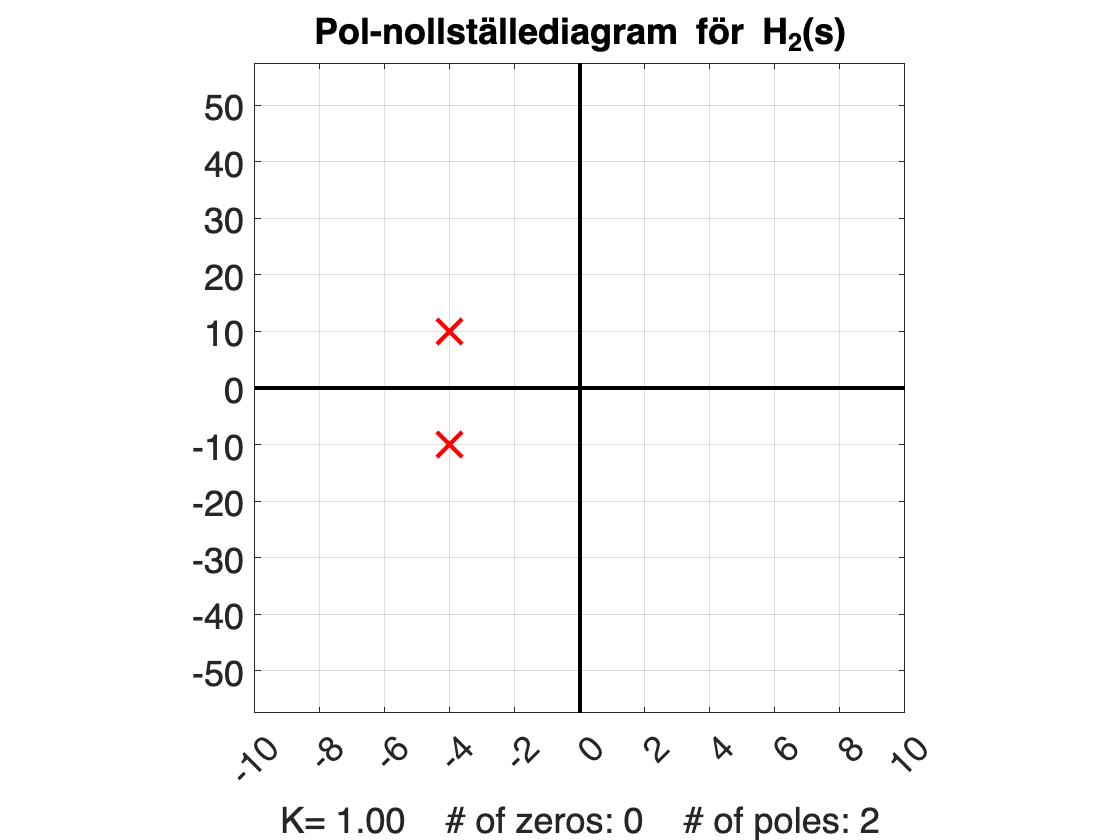

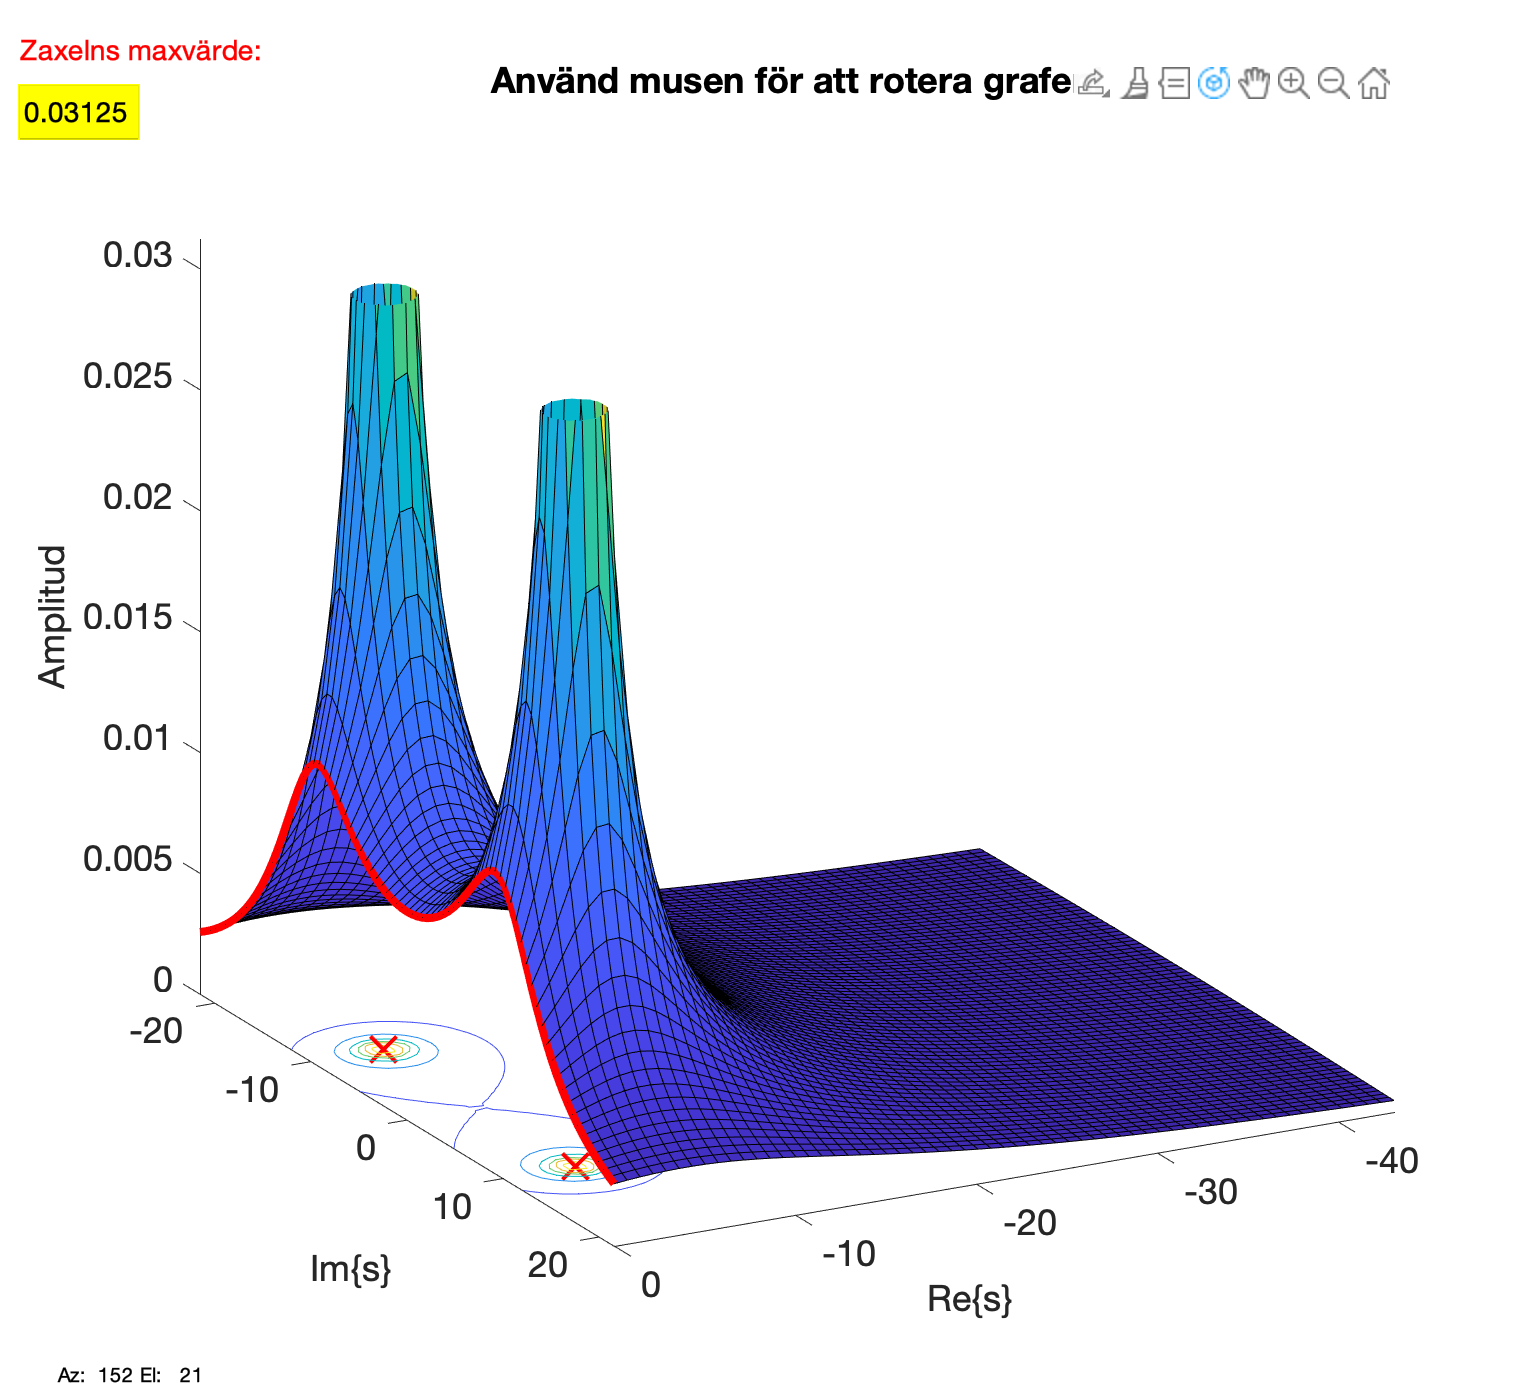

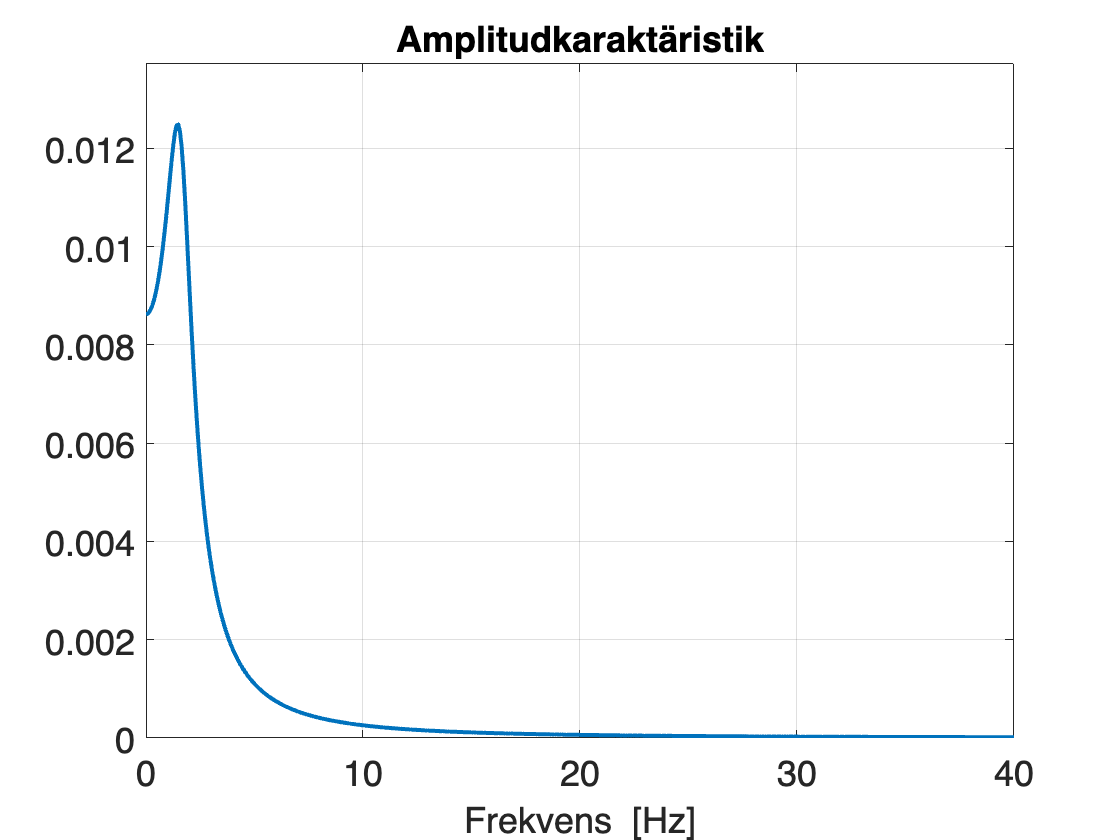

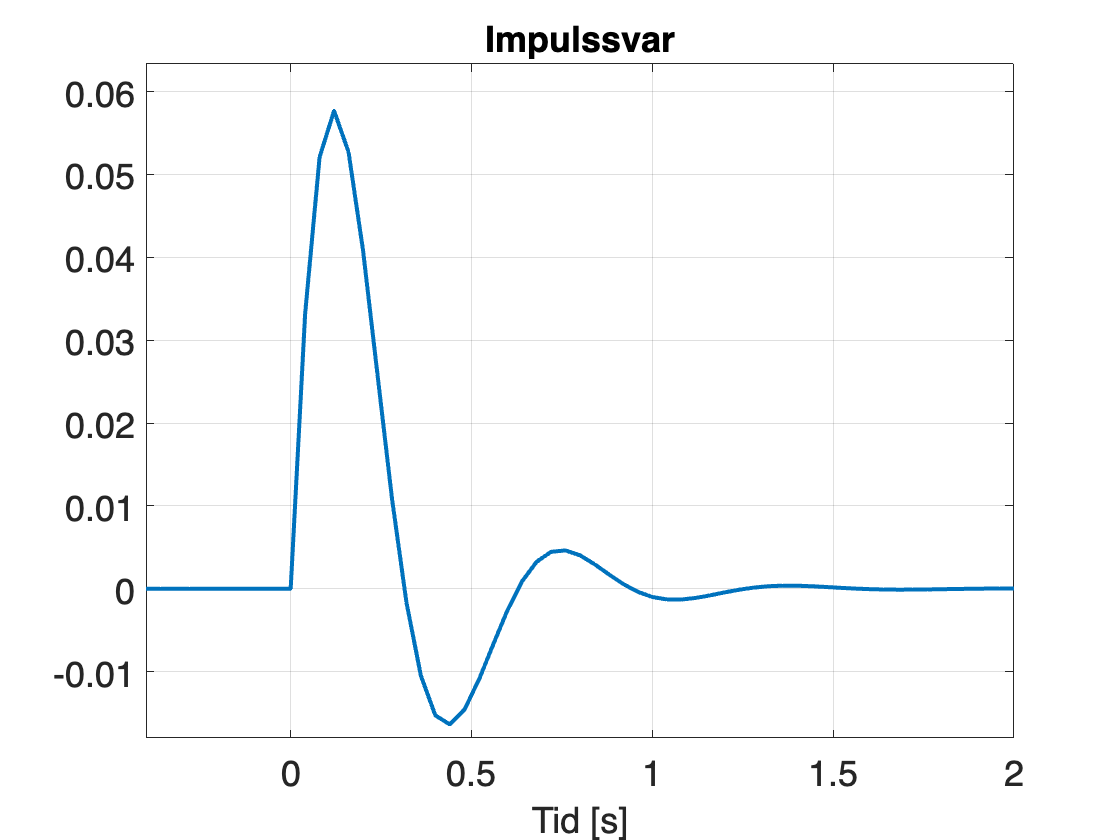

alt=3; uppgift42

När du har sparat ditt filter, så kan du nedan se separata grafer med pol-nollställediagrammet för $H_{\textrm{HP}} \left(s\right)$ och amplitudkaraktäristiken $\left|H_{\textrm{HP}} \left(f\right)\right|$ i dB-skala, genom att klicka på knappen [Visa pol-nollställe... ] nedan. 

Du kan justera frekvensaxelns övre gräns med regeln:

 
fmax = 100;

HP-filtret är hämtat!


alt=4; uppgift42

Var placerade du HP-filtrets poler och nollställen, samt vilket värde fick nivåkonstanten?

☆  **Poler****:**  $s=\left(-133\ldotp 2896\pm 133\ldotp 2896j\right)\;$

☆  **Nollställen****:**  $s=\left(0,0\right){\;\;X\;2}$

☆  **Nivåkonstanten:** $K=1\ldotp 00$ 

☆  **Kommentera egenskaperna hos ditt HP-filter:**  

(radien på cirkeln ges av 2pi * gränsfrekvensen = 2*pi*30Hz)

Det är stabilt och kausalt HP filter med gränsfrekvens 30.04 Hz vid -3 dB. 

## Uppgift 4.3 – LP-filter av ordning 2

Ett annat LTI-system har en systemfunktion $H_{\textrm{LP}} \left(s\right)$, som också har *två poler och två nollställen*. 

Undersök om det går att välja poler, nollställen och nivåkonstant så att man erhåller ett **stabilt och amplitudnormerat lågpassfilter** med 3 dB-gränsfrekvens 30 Hz, sådant att $\lim_{f\to \infty } \left|H_{\textrm{LP}} \left(f\right)\right|=0$.

Motsvarande tips som för HP-filtret ovan gäller även här, t.ex. att du ska* testa dig fram* för att få en *känsla och förståelse *för relationer mellan polernas och nollställenas placeringar och den resulterande amplitudkaraktäristiken, att gränsfrekvensen får avvika med $\pm$0.5 Hz med mera. Det är just den *förståelsen* som du bland annat ska visa vid redovisningen.

Om du redan har skapat och sparat ett lågpassfilter (LP-filter), så kan du ladda in det i Matlab genom att klicka på knappen [Ladda LP-filtret]:

Laplacetransform!


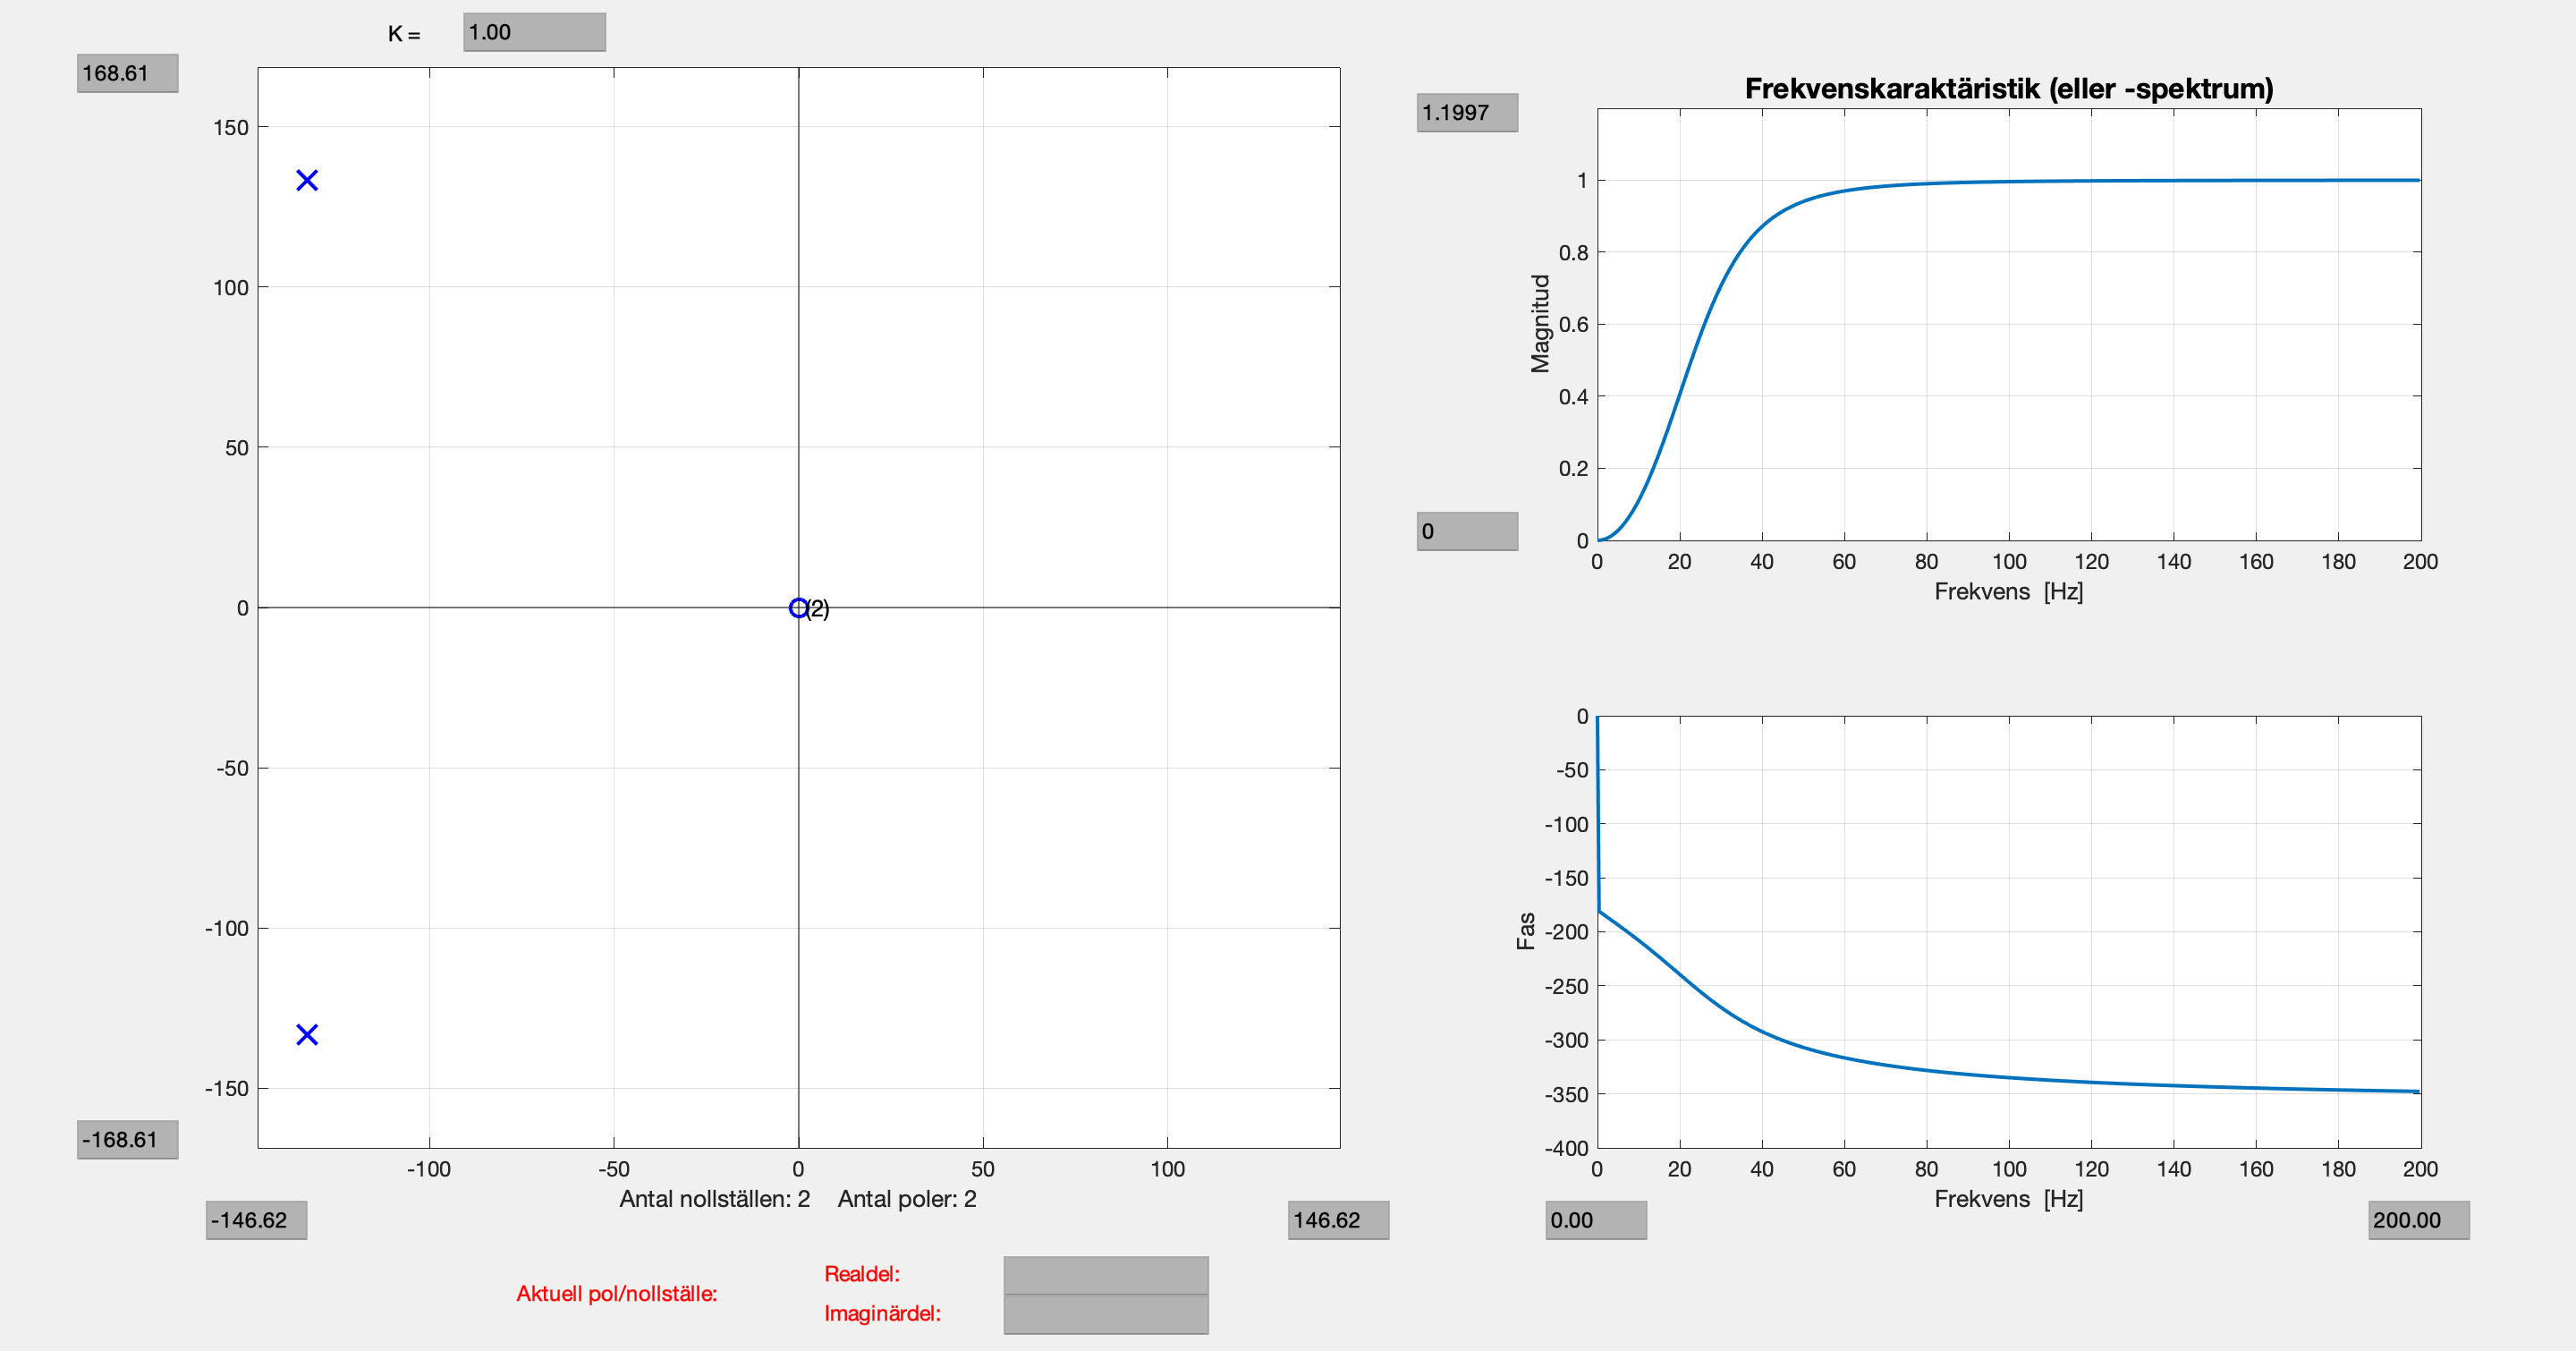

 
alt=1; uppgift43

Klicka på knappen [Starta pzchange] nedan för att starta `pzchange` med ditt skapade/sparade LP-filter. Om det är första gången du gör detta, så startar `pzchange` med $H_{\textrm{LP}} \left(s\right)=1$. På samma sätt som när du skapade HP-filtret ovan, så kommer *två* `pzchange`-fönster att öppnas/visas – en version i skript-dokumentet och en version i ett fristående `pzchange`-fönster. Även här är det i det *fristående *fönstret du ska jobba med `pzchange`.

 
alt=2; uppgift43

HP-filtret är sparat!


När du i `pzchange `är klar med ditt LP-filter, så klickar du på knappen [Spara LP-filtret] nedan. Då sparas din systemfunktion som variabeln H_LP i datafilen Uppgift43.

***OBS****: Gör detta ****innan**** du startar *`pzchange`* igen, för *`pzchange`* kan bara hantera ****en transform i taget****!! (Transformen lagras som den globala variabeln TRMF.)*

 
alt=3; uppgift43

När du har sparat ditt filter, så kan du nedan se separata grafer med pol-nollställediagrammet för $H_{\textrm{LP}} \left(s\right)$ och amplitudkaraktäristiken $\left|H_{\textrm{LP}} \left(f\right)\right|$ i dB-skala, genom att klicka på knappen [Visa pol-nollställe... ] nedan. 

Du kan justera frekvensaxelns övre gräns med regeln:

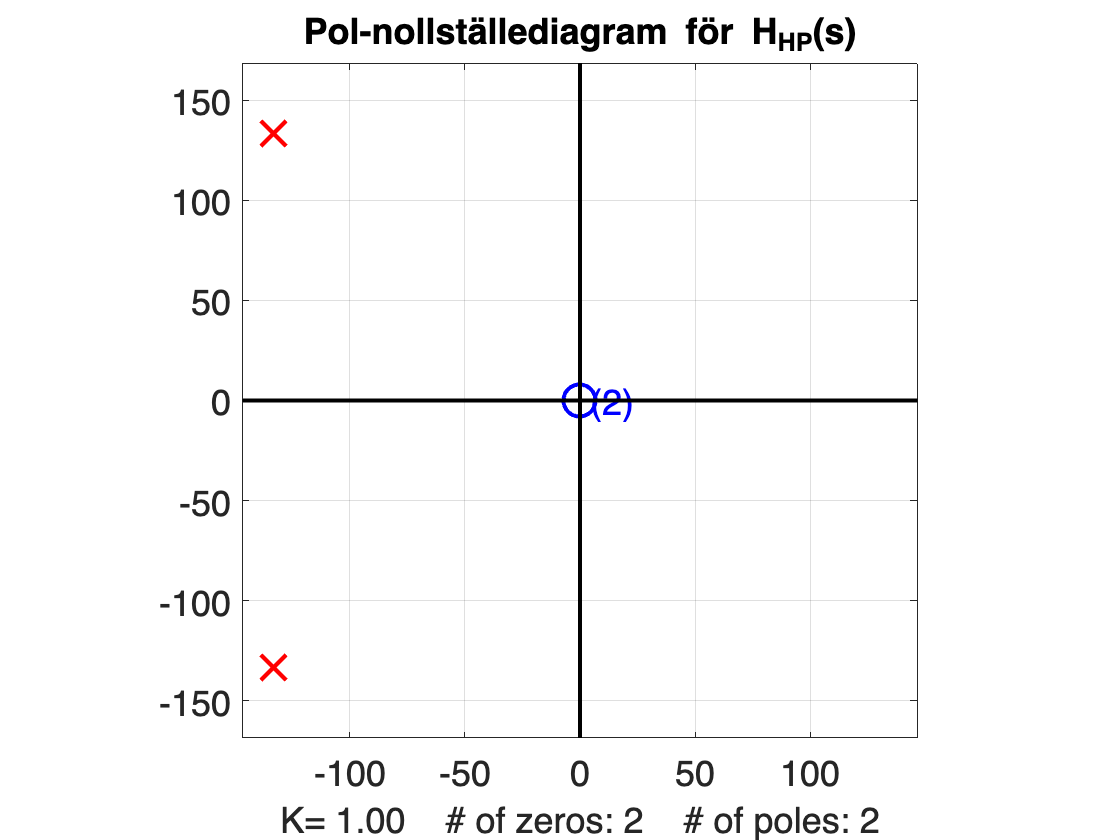

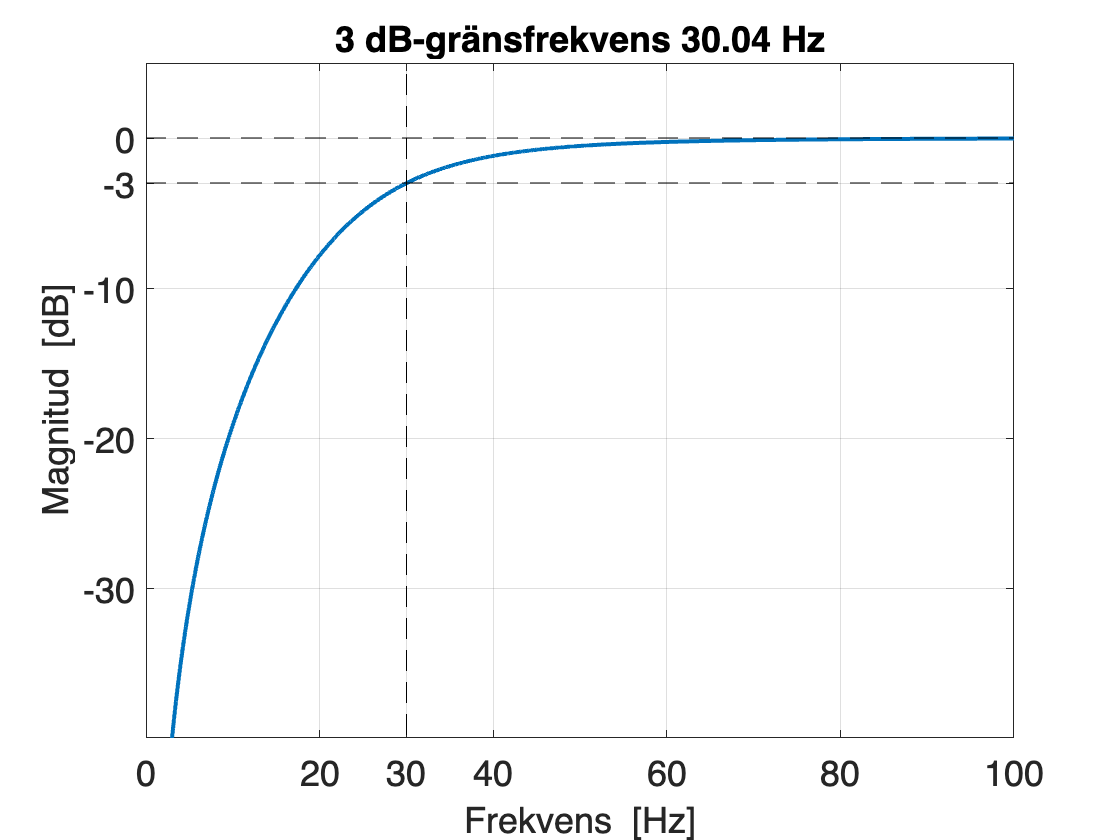

fmax = 800;
alt=4; uppgift43

Kunde du skapa ett lågpassfilter enligt *alla* kriterierna ovan? Förklara/motivera!

Som vägledning i din filterkonstruktion och din förklaring kan du bland annat reflektera/resonera över följande:

- Vad gäller allmänt för amplitudkaraktäristiken då frekvensen går mot oändligheten, dvs. $\lim_{f\to \infty } \left|H_{\textrm{LP}} \left(f\right)\right|$ i detta fall, för systemfunktioner där antalet nollställen är lika med antalet poler? 

- Var är det lämpligt att placera polerna och nollställena, samt vilket värde får då nivåkonstanten, när du designar ett LP-filter som åtminstone ger ett bra utseende i passbandet och en *hyfsat bra *dämpning i spärrbandet?

☆  **Svar:**  

I allmänt gäller det att  $\lim_{f\to \infty } \left|H_{\textrm{LP}} \left(f\right)\right|=0$. 

Hur bra LP-filter kan du trots allt få till med dina två poler och två nollställen, dvs. hur bra dämpningsegenskaper har det i passbandet och i spärrbandet?

☆  **Poler****:**  $s=\left(-133\ldotp 2896;133\ldotp 2896\right),\left(-133\ldotp 2896;-133\ldotp 2896\right)$

☆  **Nollställen****:**  $s=\left(\infty ,0\right)\;\;2x$

☆  **Nivåkonstanten:** $K=0\ldotp 01$ 

☆  **Kommentera egenskaperna hos ditt LP-filter:**  

Vi har ett LP filter med gränsfrekvens 29.98 Hz för -3dB.  

## Uppgift 4.4 – Butterwortfilter & Chebyshevfilter

Matlabfunktionerna `butter` och `cheby1` genererar systemfunktionerna till **butterworthfilter **respektive** chebyshev I-filter**. Funktionerna finns i **Signal Processing Toolbox**, som ingår i den Matlab-licens som du använder. 

**OBS: Om du använder egen dator, så se till att du har installerat toolboxen innan du fortsätter!**

När du nedan klickar på knappen [Visa ...] så ritas pol-nollställediagrammet till butterworthfiltrets systemfunktion $H_B \left(s\right)$ och filtrets amplitudkaraktäristik $\left|H_B \left(f\right)\right|,$ för de förinställda parametervärdena. Du ser ett *amplitudnormerat ***butterworthfilter** av lågpasstyp, med ordning *N* (dvs. systemfunktionen har *N* poler) och 3 dB-gränsfrekvens 100 Hz (*även om det numeriska värdet för gränsfrekvensen i grafen avviker lite*):

Studera sedan hur pol-nollställediagrammet och amplitudkaraktäristiken ändras när du med den översta regeln ändrar filtrets ordning *N*. Med den andra regeln bestämmer du frekvensskalans övre gräns och med den tredje regeln bestämmer du dB-skalans undre gräns:

 
N = 10;

LP-filtret är hämtat!


fmax = 400;
dBmin = -130;
uppgift441

Med hur många dB dämpar ett butterworthfilter med ordning $N=10$ en sinusformad insignal $x_1 \left(t\right)$ med frekvensen 150 Hz och med hur många dB dämpar detta filter en sinusformad insignal $x_2 \left(t\right)$ med frekvensen 400 Hz? (*Zooma in i grafen!*)

☆  **Svar **(*en decimals noggrannhet räcker*)**:**  

För 150 Hz: -3.6dB

För 400 Hz: -12.0dB

Nedan används istället ett motsvarande **chebyshev I-filter** med 3 dB rippel och med samma 3 dB-gränsvinkelfrekvens som butterworthfiltret ovan, dvs. 100 Hz. Klicka först på knappen [Visa ...] för att visa pol-nollställediagrammet till chebyshevfiltrets systemfunktion $H_C \left(s\right)$ och filtrets amplitudkaraktäristik $\left|H_C \left(f\right)\right|$ för de förinställda parametervärdena.

Studera sedan hur pol-nollställediagrammet och amplitudkaraktäristiken ändras när du med den översta regeln ändrar filtrets ordning *N*. 

Med den andra regeln bestämmer du frekvensskalans övre gräns och med den tredje regeln bestämmer du dB-skalans undre gräns:

Laplacetransform!


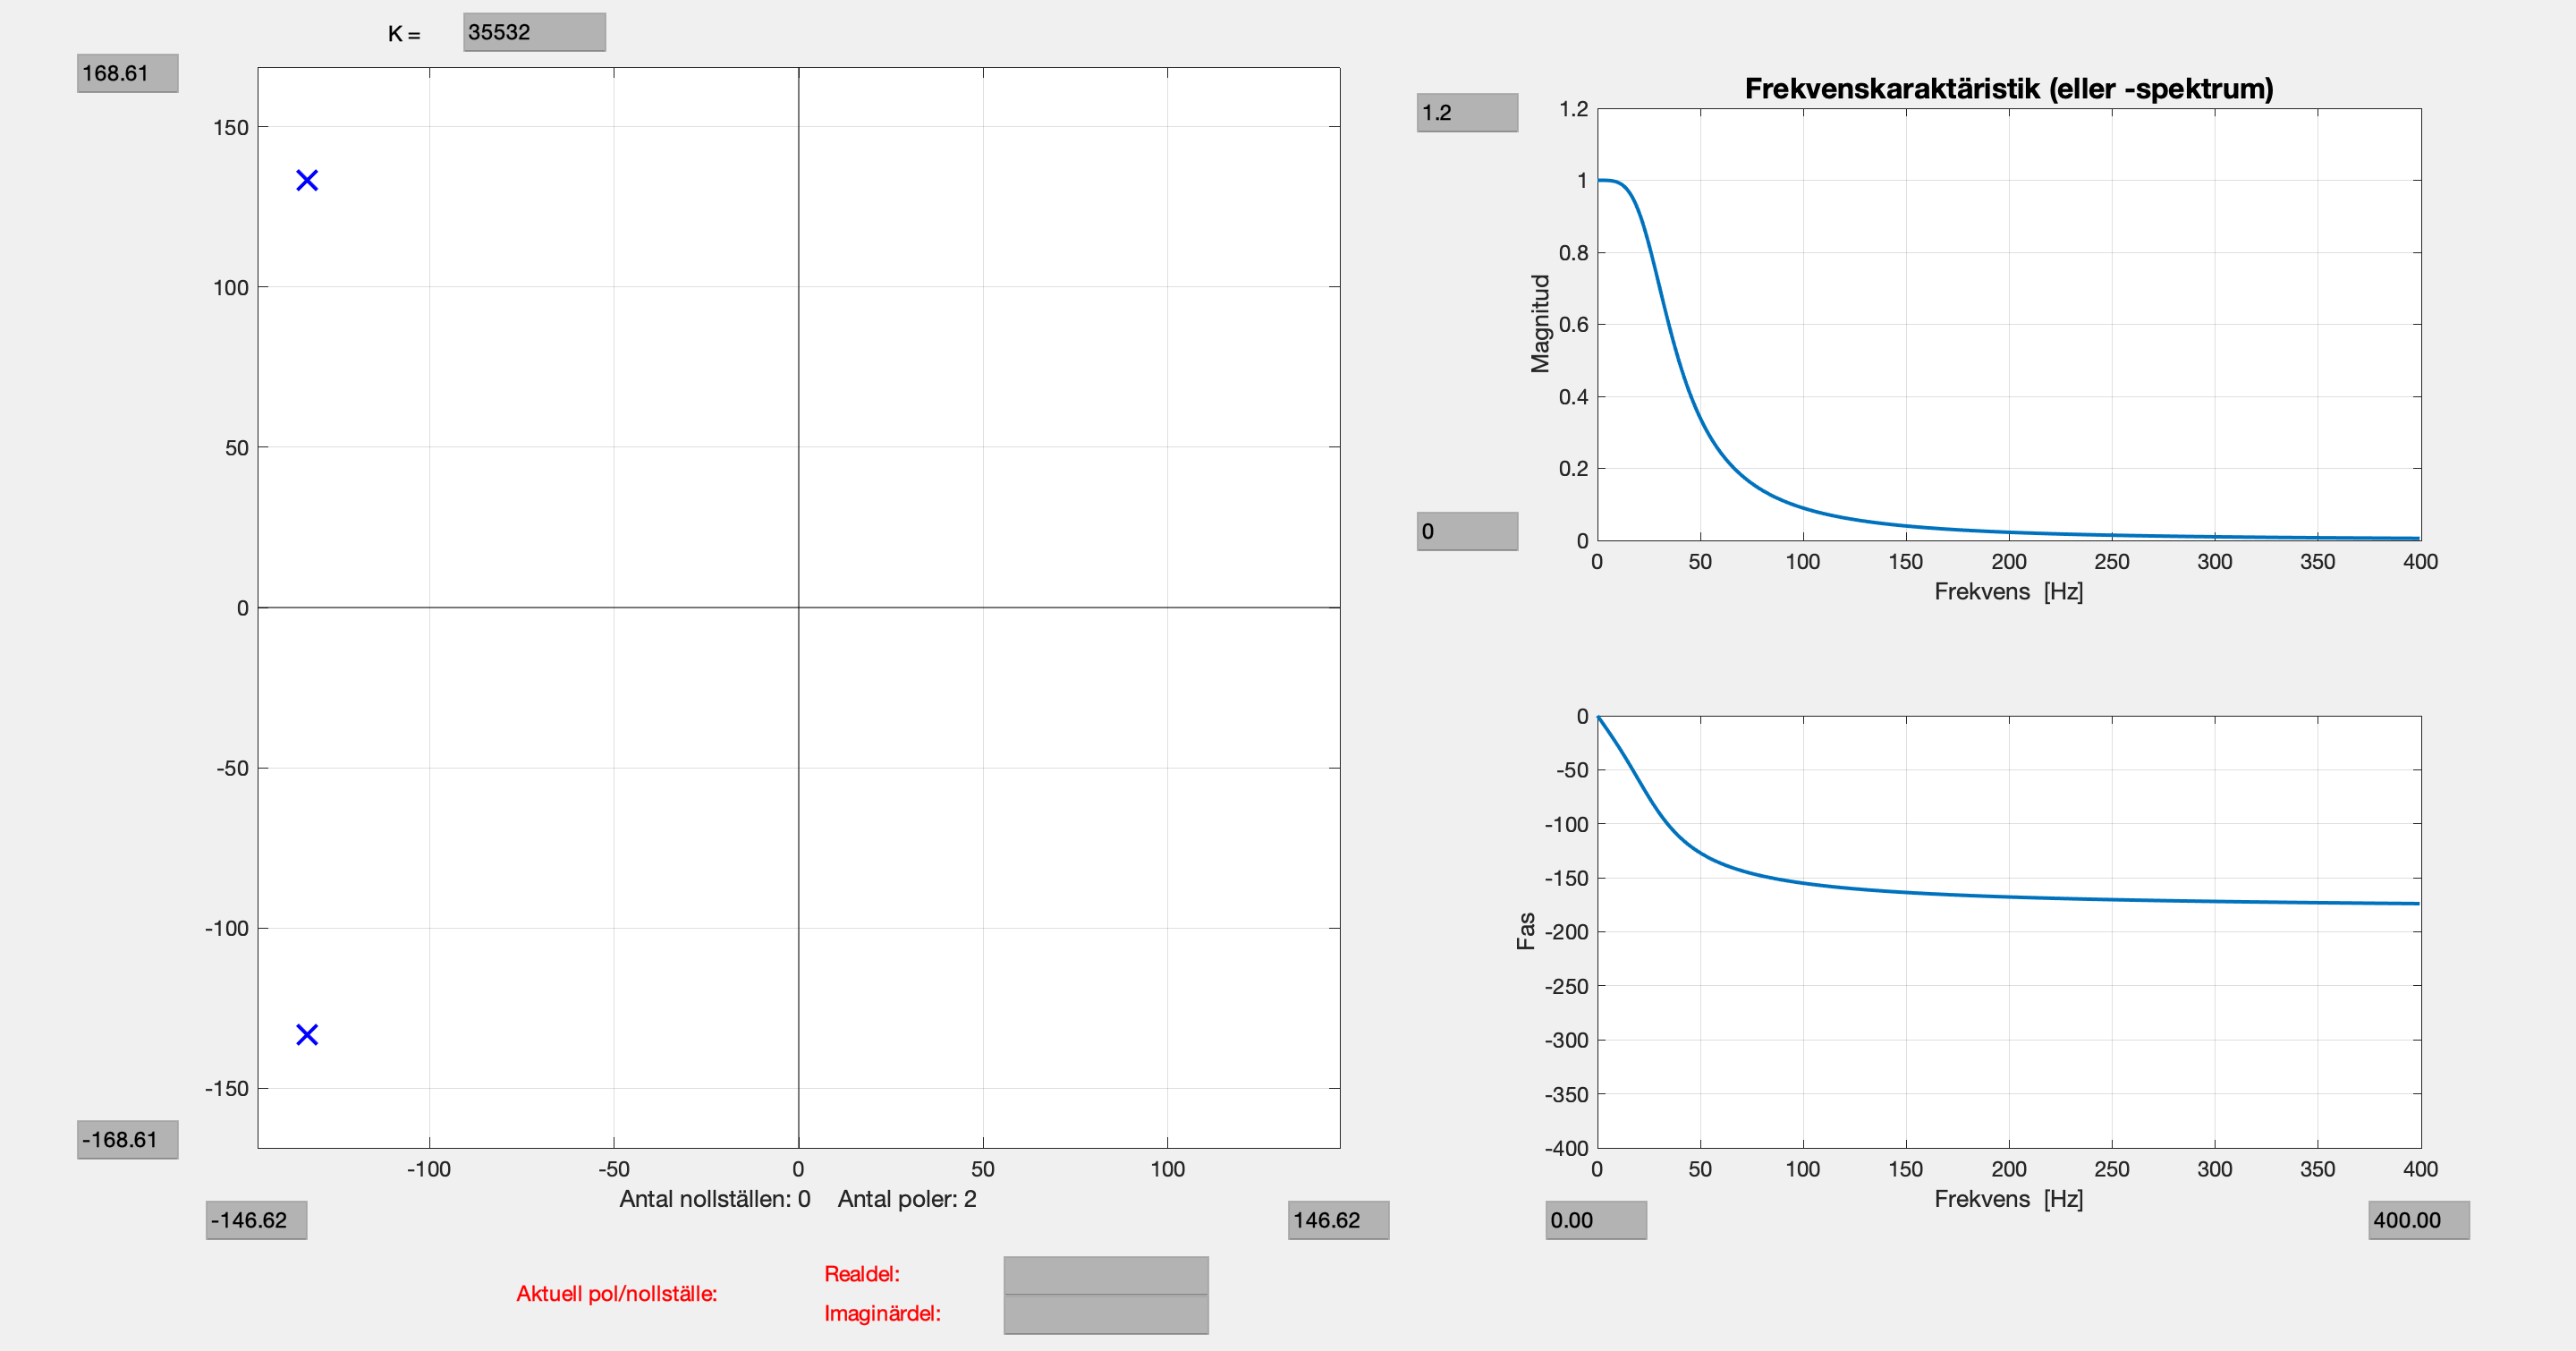

N = 5;
fmax = 400;
dBmin = -100;
uppgift442

Vilken är den *lägsta ordning* chebyshevfiltret kan ha och fortfarande dämpa den sinusformade signalen $x_1 \left(t\right)$ minst lika mycket som butterworthfiltret av ordning 10 ovan? Med hur många dB (*en decimals noggrannhet räcker*) dämpar detta chebyshevfilter den sinus-formade signalen $x_2 \left(t\right)$?

☆  **Svar:**  

N = 5, vi ser att butterworthfiltret dämpar med ungefär -35 dB. Om vi ändrar N för det andra filtret ser vi att N från 5 tom 10 ger en dämpning på minst 35 dB. 

Kommentera resultaten – bland annat *vilket* filter du tycker är bäst och *varför*.  

☆  **Kommentar:**  

Det beror på, båda har kvaliteer som är eftertraktade. Till exempel har chebyshev snabbare övergångar än butterworth, medans butterworth inte skapar någon fasförskjutning. 

## Uppgift 4.5 – Bandpassfiltrering av en DTMF-signal

I DTMF-signalen `toner`, som du undersökte i Uppgft 3.3–3.4 i Laboration 2, kan det vara av intresse att ta reda på vilka knapptryckningar som innehåller en sinussignal med en viss frekvens. Det kan man göra genom att filtrera bort alla frekvenskomponenter utom just den som är av intresse. 

                    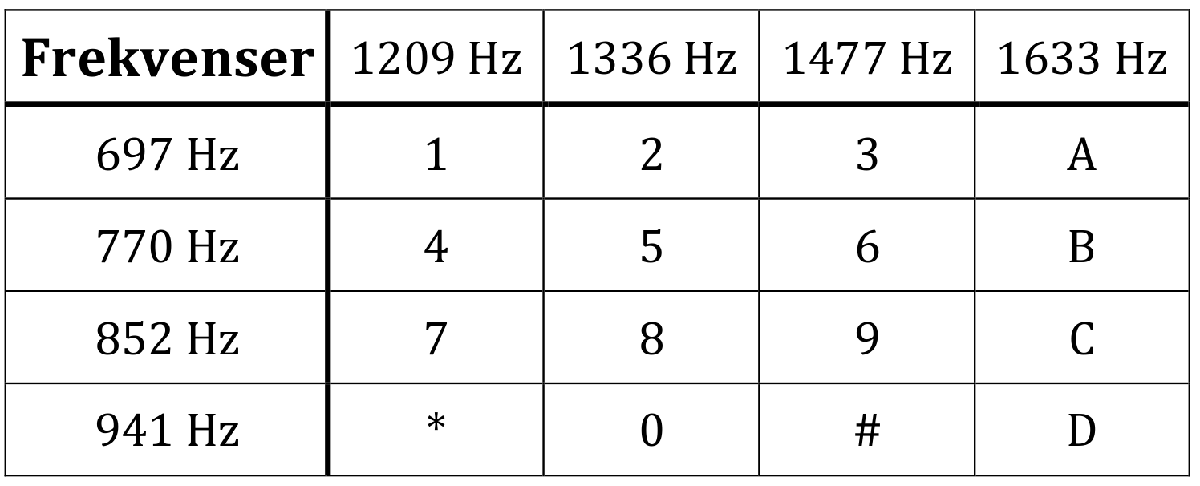

Av DTMF-tabellen ovan framgår det att sinussignal-pulser med frekvenserna 941 Hz och 1209 Hz ingår i en DTMF-puls då någon av telefonknapparna ”*”, ”0”, ”#” eller ”D” respektive ”1”, ”4”, ”7” eller ”*” tryckts ned. Eftersom det inte finns någon annan DTMF-puls med frekvens mellan 941 Hz och 1209 Hz, kan vi *filtrera fram dessa två frekvenskomponenter *genom att låta DTMF-signalen `toner` passera genom ett lämpligt **bandpassfilter**.

Tag fram ett amplitudnormerat, kausalt och stabilt bandpassfilter av **högst ordning 6** (dvs. dess systemfunktion har *högst* $N=6$ poler) genom att, m.h.a. `pzchange`, placera ut systemfunktionens poler och nollställen på lämpliga ställen i *s*-planet.

Justera deras lägen i *s*-planet för hand, tills du erhåller önskad amplitudkaraktäristik. Du ska/får **inte** använda en filtergenererande funktion likt `butter` eller `cheby1`, här är det tänkt att du först ska tänka igenom *ungefär* var poler och nollställen bör placeras. Sedan placerar du och flyttar dem *för hand* tills du uppnår filterkraven tillräckligt bra. Det är rätt *mjuka krav*, så håll inte på ”onödigt” länge med att få till något exakt.

**Filterkrav**: Frekvenskomponenterna vid $f_{\textrm{p1}} =941\;$Hz och $f_{\textrm{p2}} =1209$ Hz får inte dämpas med mer än ca 3 dB och dämpningen vid $f_{\textrm{s1}} =900$ Hz och $f_{\textrm{s2}} =1250$ Hz skall vara *minst* ca 6 dB. Dessa filterkrav illustreras av följande graf, som du känner igen från föreläsningarna om frekvensselektiva filter, där amplitudkaraktäristiken ${\left|H\left(f\right)\right|}_{\textrm{dB}}$ *inte* får gå genom något av de streckade områdena:

             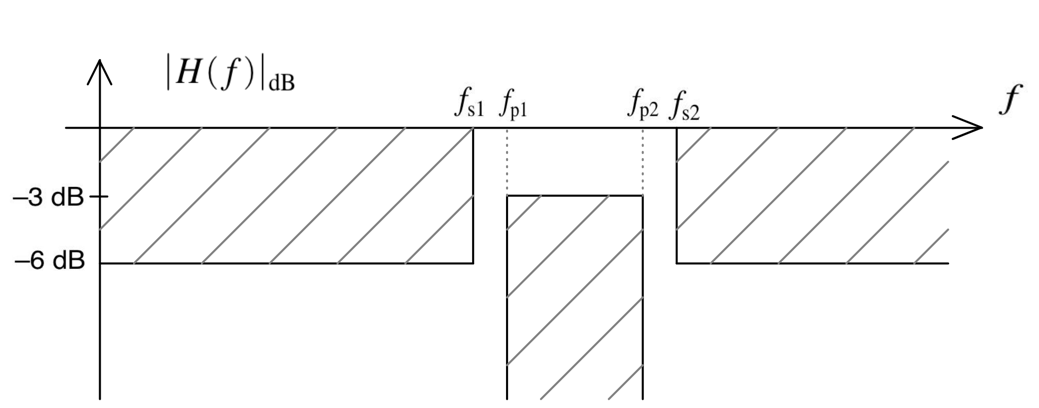

**Tips och vägledande information:**

- Uppgiften blir onödigt tidskrävande om du börjar med att sporadiskt placera ut poler & nollställen. Hur skulle Butterworth ha resonerat?

- Det är OK med rippel i passbandet – men på max 3 dB, för det är ju ett BP-filter (med *ett *passband) som du ska skapa. Amplitudkaraktäristiken ${\left|H_{\textrm{BP}} \left(f\right)\right|}_{\textrm{dB}}$ får alltså **inte inte gå under –3 dB mellan eventuella toppar i passbandet**.

- Övre och nedre övergångsbanden är lika breda (941–900= 1250–1209).

- Det här är en uppgift där tanken är att du skall få en *känsla och förståelse* för hur poler och nollställen samverkar för att ge önskad amplitudkaraktäristik. Använd kunskaper och förståelse som du fick när du jobbade med de två systemen i Uppgift 4.1 samt med HP-filtret i Uppgift 4.2 och LP-filtret i Uppgift 4.3!

Om du redan har skapat och sparat ett bandpassfilter (BP-filter), så kan du ladda in det i Matlab genom att klicka på knappen [Ladda BP-filtret]:

LP-filtret är sparat!


uppgift451

Klicka på knappen [Starta pzchange] nedan för att starta `pzchange` med ditt skapade/sparade BP-filter. Om det är första gången du gör detta, så startar `pzchange` med $H_{\textrm{BP}} \left(s\right)=1$. På samma sätt som när du skapade LP-/HP-filtren ovan, så kommer *två* `pzchange`-fönster att öppnas/visas – en version i skript-dokumentet och en version i ett fristående `pzchange`-fönster. Även här är det i det *fristående *fönstret du ska jobba med `pzchange`.

 
uppgift452

När du i `pzchange `är klar med ditt BP-filter, så klickar du på knappen [Spara BP-filtret] nedan. Då sparas din systemfunktion som variabeln H_BP i datafilen Uppgift45.

***OBS****: Gör detta ****innan**** du startar *`pzchange`* igen, för *`pzchange`* kan bara hantera ****en transform i taget****!! (Transformen lagras som den globala variabeln TRMF.)*

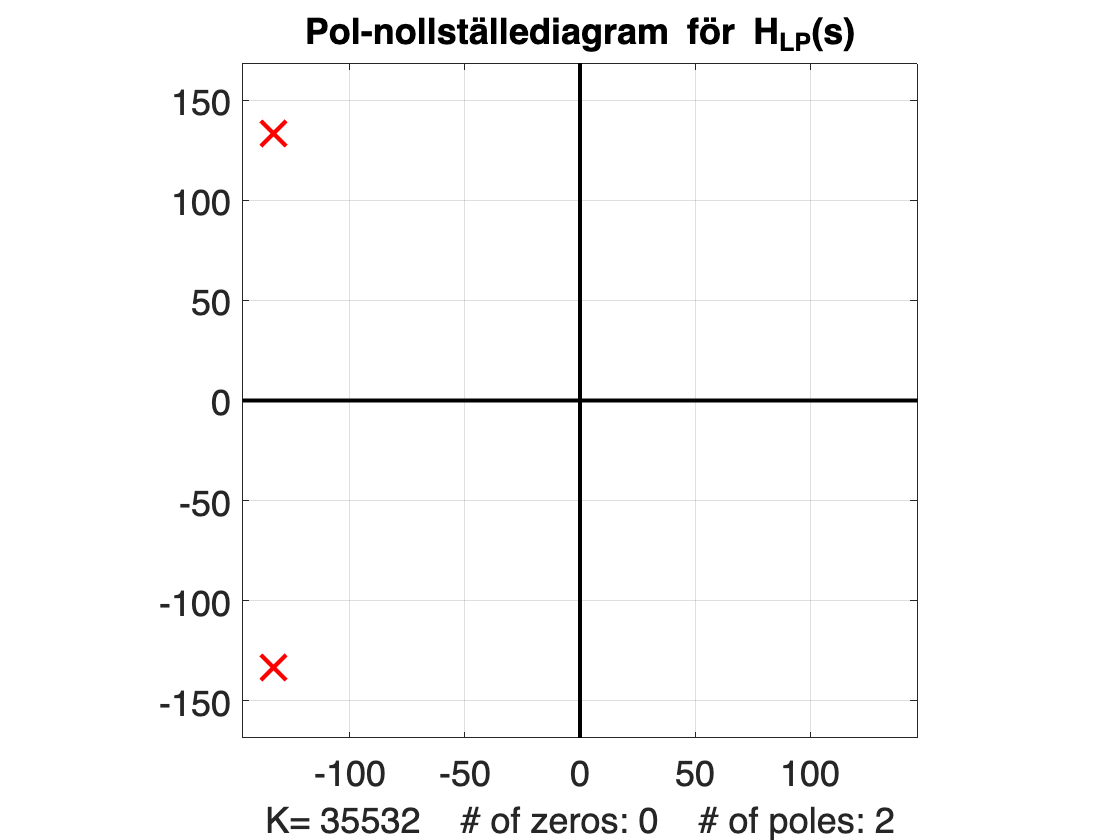

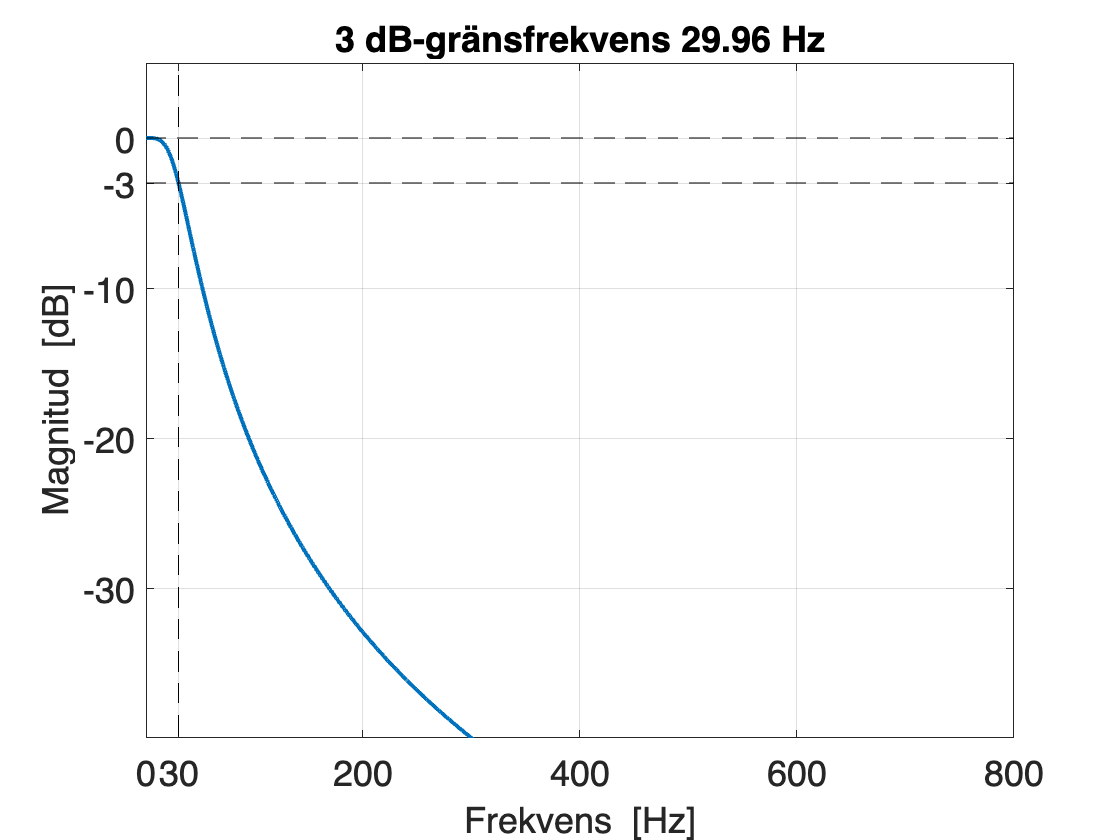

uppgift453

Klicka på knappen nedan för att kontrollera att filtret uppfyller dämpningskraven, dvs. 

- *högst* 3 dB dämpning vid 941 Hz och 1209 Hz

- *minst* 6 dB dämpning vid 900 Hz och 1250 Hz

*Aktuella dämpningar skrivs ut i textform. *

*Om du klickar på knappen innan du skapat och sparat något filter, så kommer det att returneras en röd feltext , på grund av att skriptet inte hittar variabeln H_BP med din systemfunktion.*

 
uppgift454

När du har sparat ditt filter, så kan du nedan se separata grafer med pol-nollställediagrammet för $H_{\textrm{BP}} \left(s\right)$ och amplitudkaraktäristiken $\left|H_{\textrm{BP}} \left(f\right)\right|$, genom att klicka på knappen [Visa separata ... ]. I drop down-menyn finns två val för amplitudkaraktäristiken; 0 till 2000 Hz i linjär skala eller 900 till 1250 Hz i dB-skala. Zooma gärna (manuellt) in i graferna om du vill studera dem närmare!

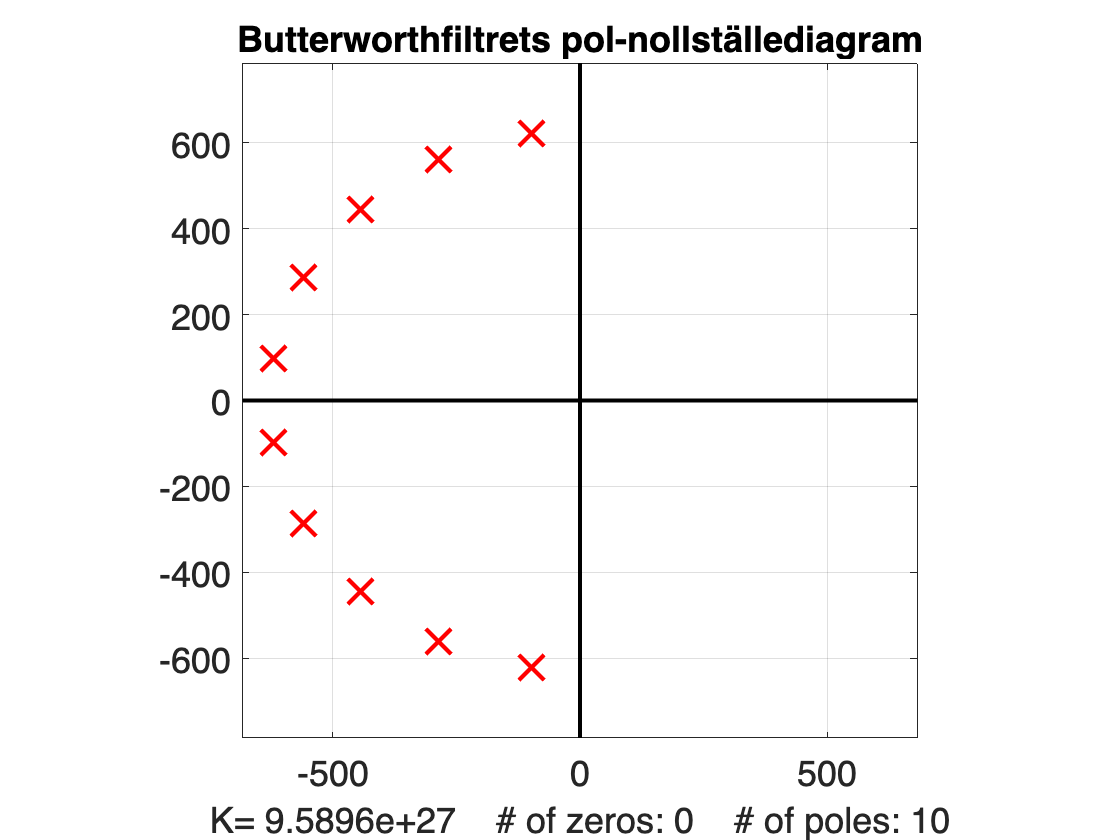

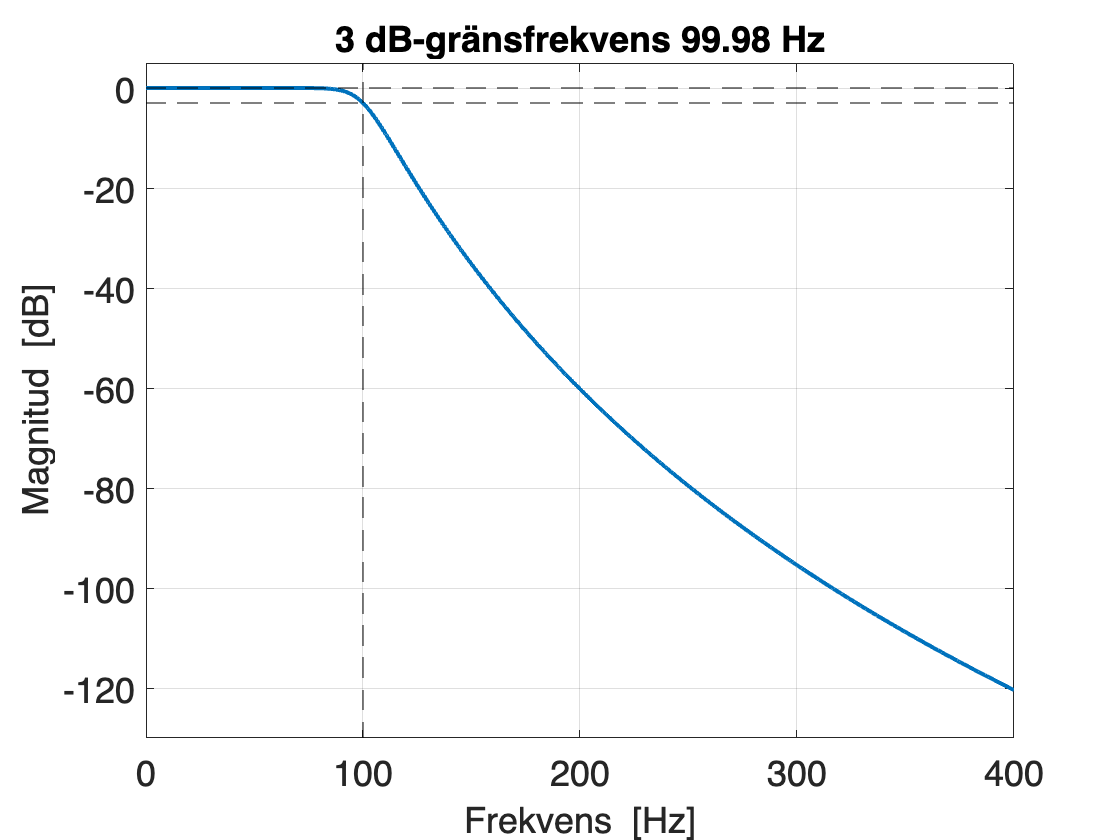

 
frekvensintervall = 1;
uppgift455

Förklara/motivera (lagom kort men tydligt) hur du resonerar, vid placeringen av systemfunktionens nollställen och poler för att erhålla önskat frekvensuppförande. Relatera lämpligen även till ditt resonemang i Uppgift 4.1.

☆  **Svar:**  Vi utgick först och främst från föreläsningsslidesen, då insåg vi att polerna bör bilda en typ av halvcirkel till vänster om alla nollställen för att få ett stabilt BP-filter. Vi började sedan med att hitta startposition för alla punkter. Dessa hamnar längs en cirkel med mittpunkten $O=\frac{f_{\textrm{p1}} +f_{\textrm{p2}} }{2}*2\pi$ och radien $r=2\pi \left(f_{\textrm{p1}} -f_{\textrm{p2}} \right)\ldotp$ Sedan försöker vi flytta imaginär- och realdel på polerna för att få en bättre kurva på bandpassfiltret. Flyttas polen längst från origo påverkar man den övre gränsen. Flyttar man den polen som är närmast origo påverkar man den undre gränsen. Polernas realdel påverkar vinkeln på grafen och imaginärdelen påverkar vart i sidled kurvan är placerad. (Vi ändrade runt och såg vad som blev annorlunda). 

Ange även polernas och nollställenas lägen (*menyval "Print/Type" i *`pzchange`) samt nivåkonstanten (skriv gärna komplexkonjugerade par på formen $s=a\pm \textrm{jb}$) .

☆  **Poler:**  $s=\left(-400\pm 5900j\right),\left(-757\pm 6600j\right),\left(-450\pm 7500j\right)\;\;$

☆  **Nollställen:**  $s=\;\left(0+0j\right)$ (3 st)

☆  **Nivåkonstant:**  $K=4\ldotp 9731*{10}^9$

## Uppgift 4.6 – Bestäm DTMF-signalens knapptryckningar

Använd, enligt beskrivningen i föregående uppgift, ert filter för att ta reda på vilka av DTMF-pulserna som representerar någon/några av knapptryckningarna ”0”, ”1”, ”4”, ”7”, ”*”, ”#” eller ”D”. Ladda först in DTMF-signalen `toner`, som du undersökte i Uppgft 3.3–3.4 i Laboration 2, samt ditt BP-filter:

 
uppgift461

Markera själv nedan vilka grafer som ska ritas och studera hur bandpassfiltret har påverkat dess insignal, dvs. DTMF-signalen, både i tidsdomänen och i frekvensdomänen. Zooma gärna för hand, vid behov, i graferna för att studera dem närmare:

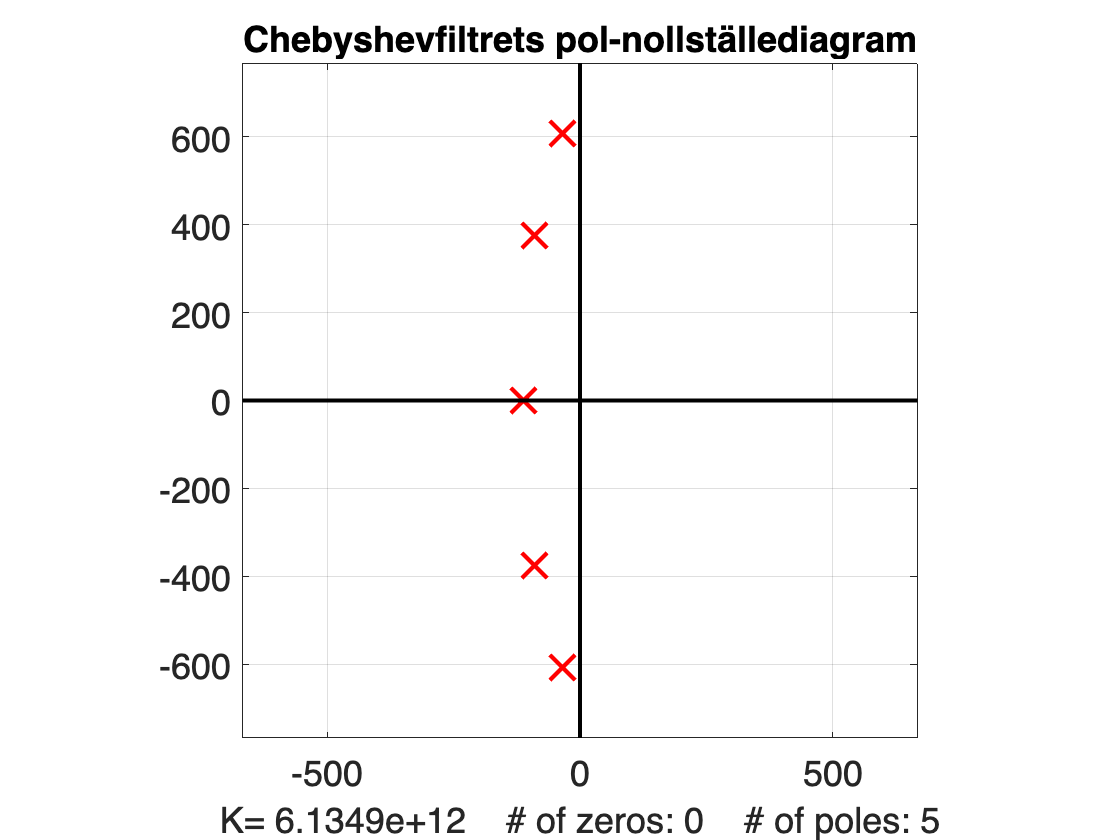

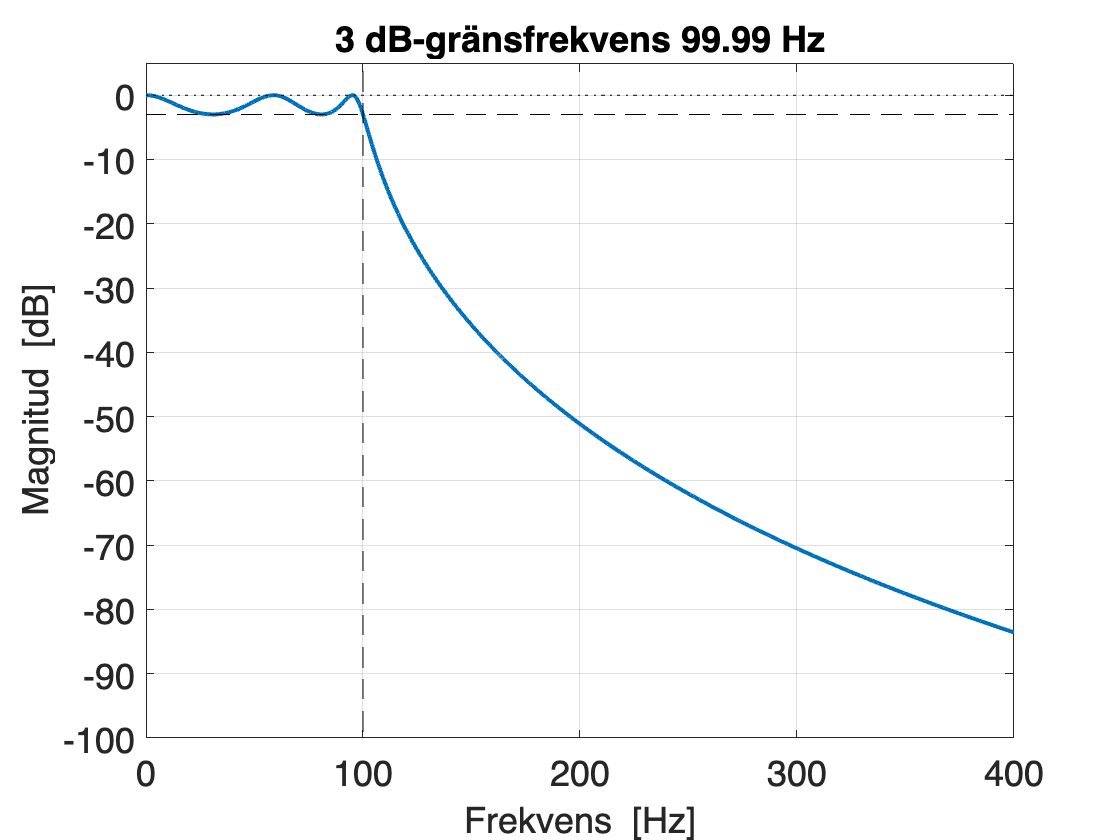

Insignal = true;   % Rita DTMF-signalen (BP-filtrets insignal)
INSPEKTRUM = false; % Rita DTMF-signalens amplitudspekteum
AMPLKAR = false;    % Rita BP-filtrets amplitudkaraktäristik

BP-filtret är hämtat!


Laplacetransform!


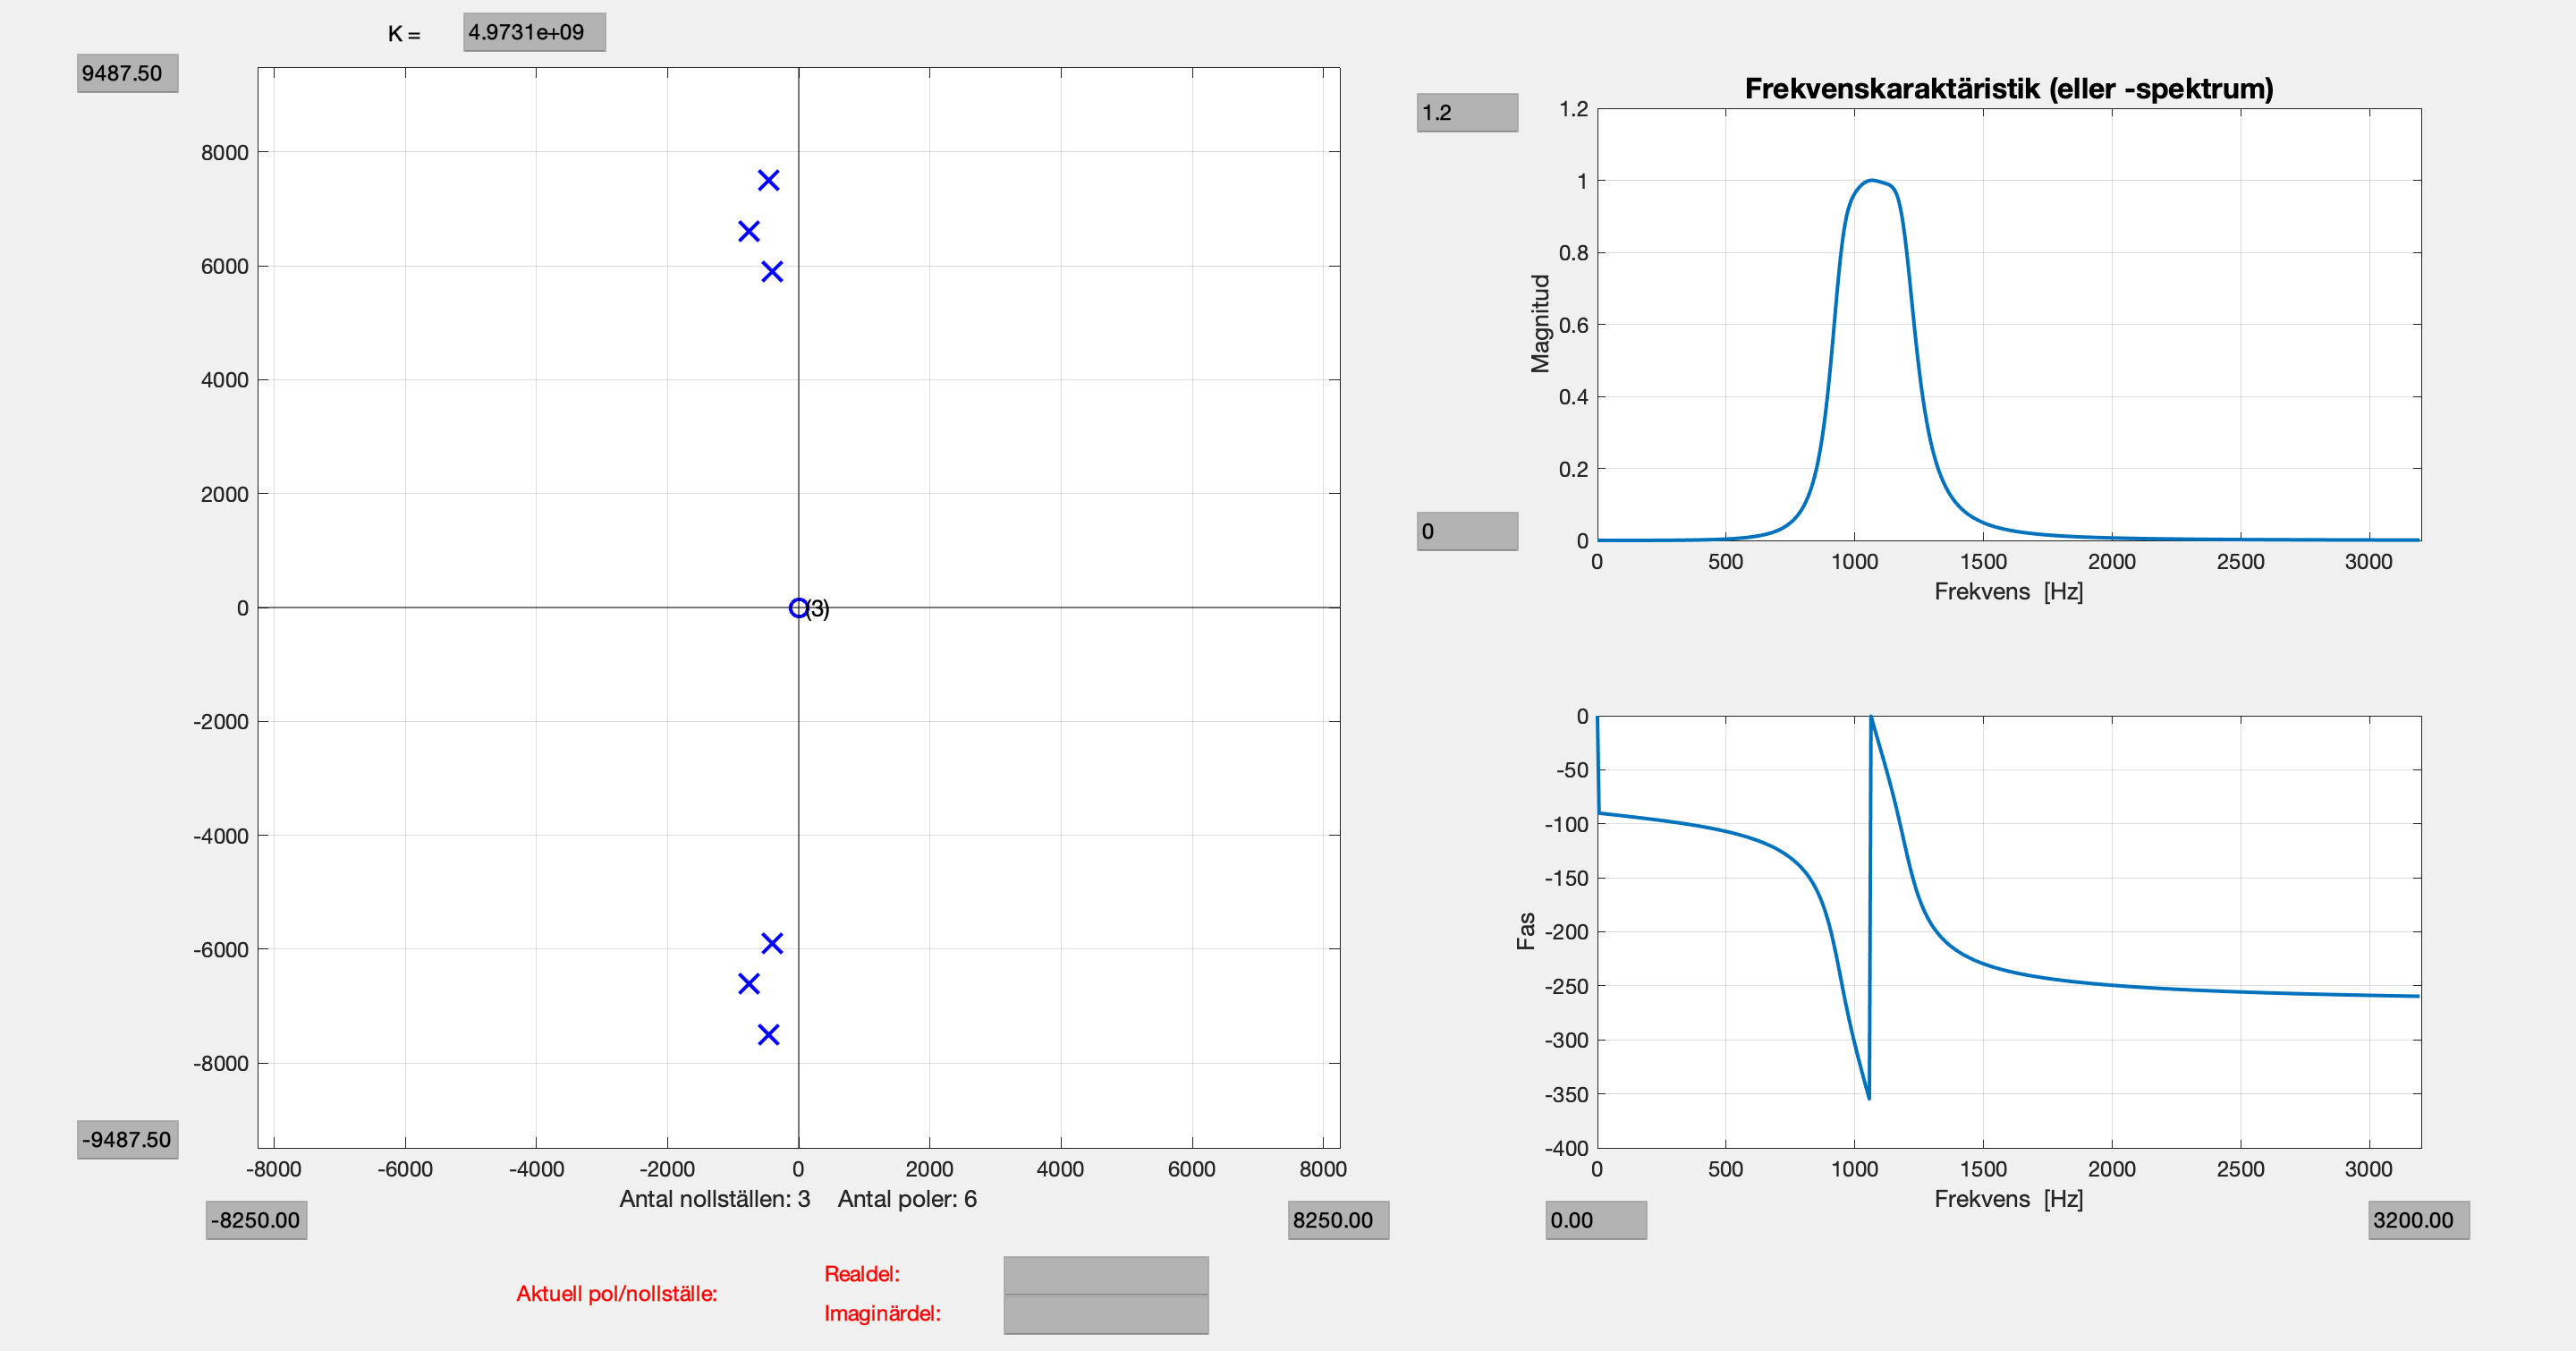

BP-filtret är sparat!


Ditt bandpassfilter dämpar enligt följande:
  * 7.0 dB dämpning vid 900 Hz
  * 2.3 dB dämpning vid 941 Hz
  * 2.5 dB dämpning vid 1209 Hz
  * 6.5 dB dämpning vid 1250 Hz


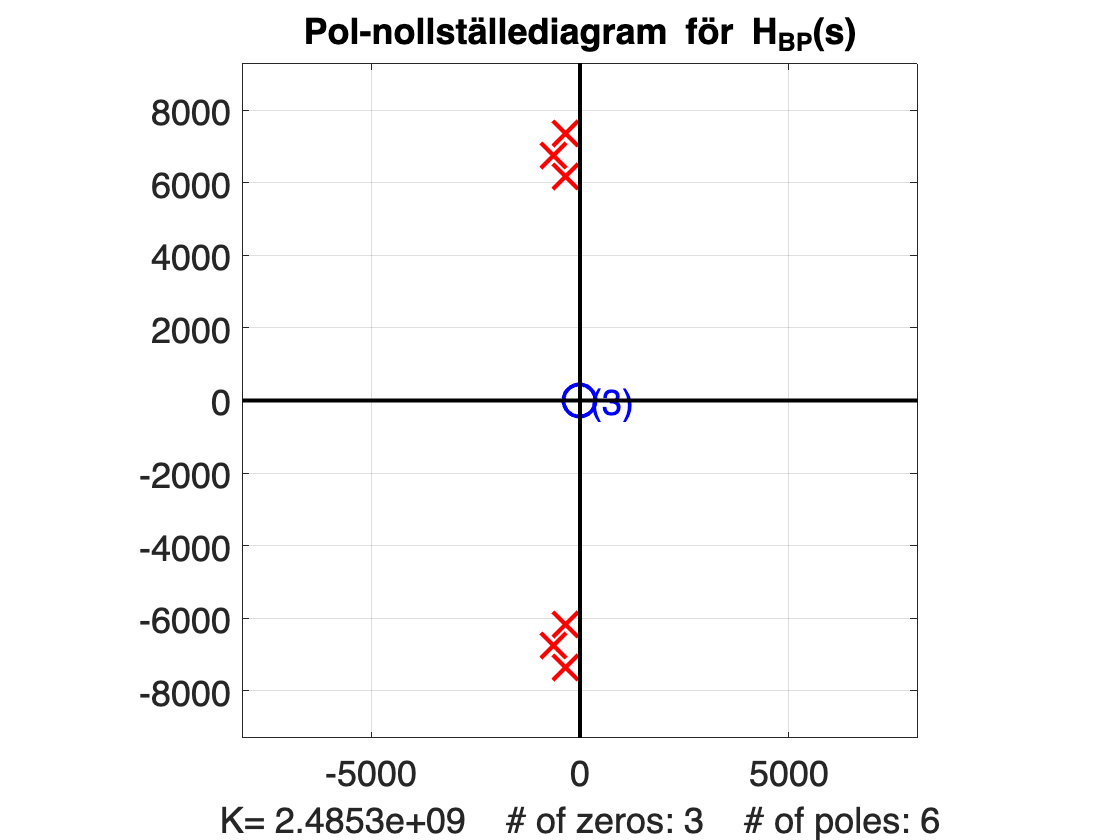

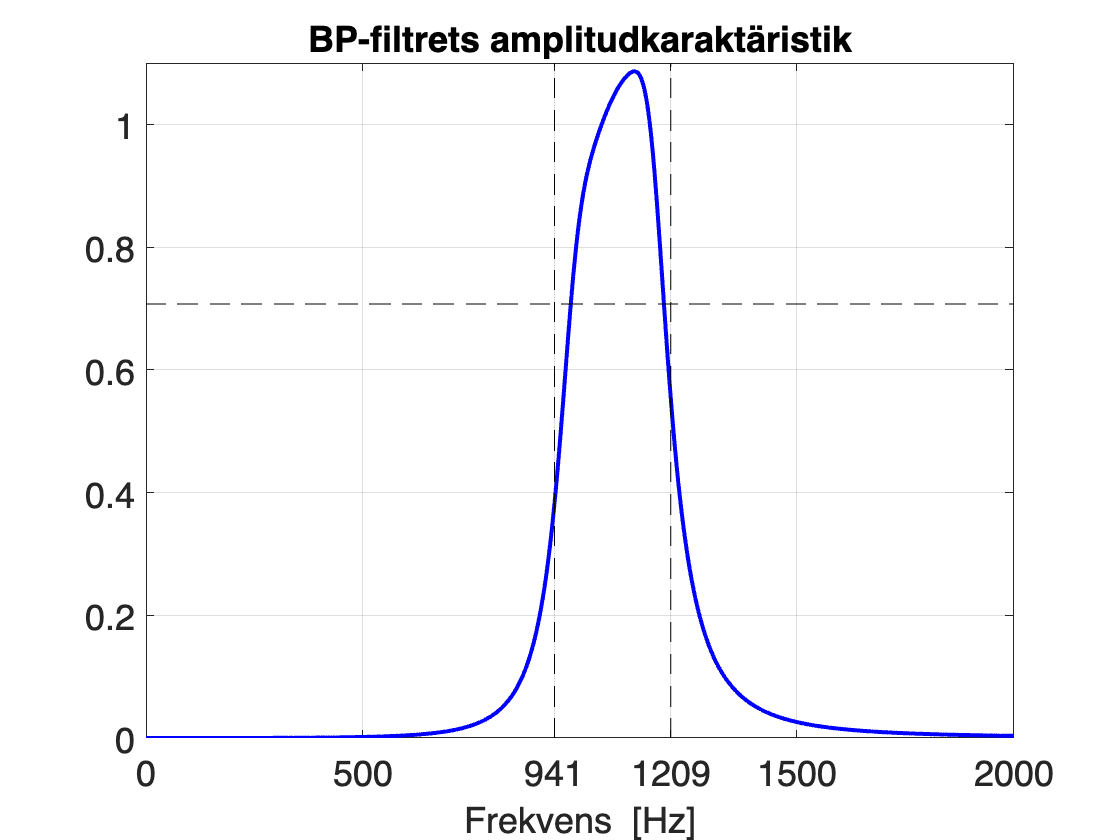

BP-filtret och 'toner' är hämtade!
Jobbar lite...
Utsignalsform: 
Fouriertransform av tidskontinuerlig signal


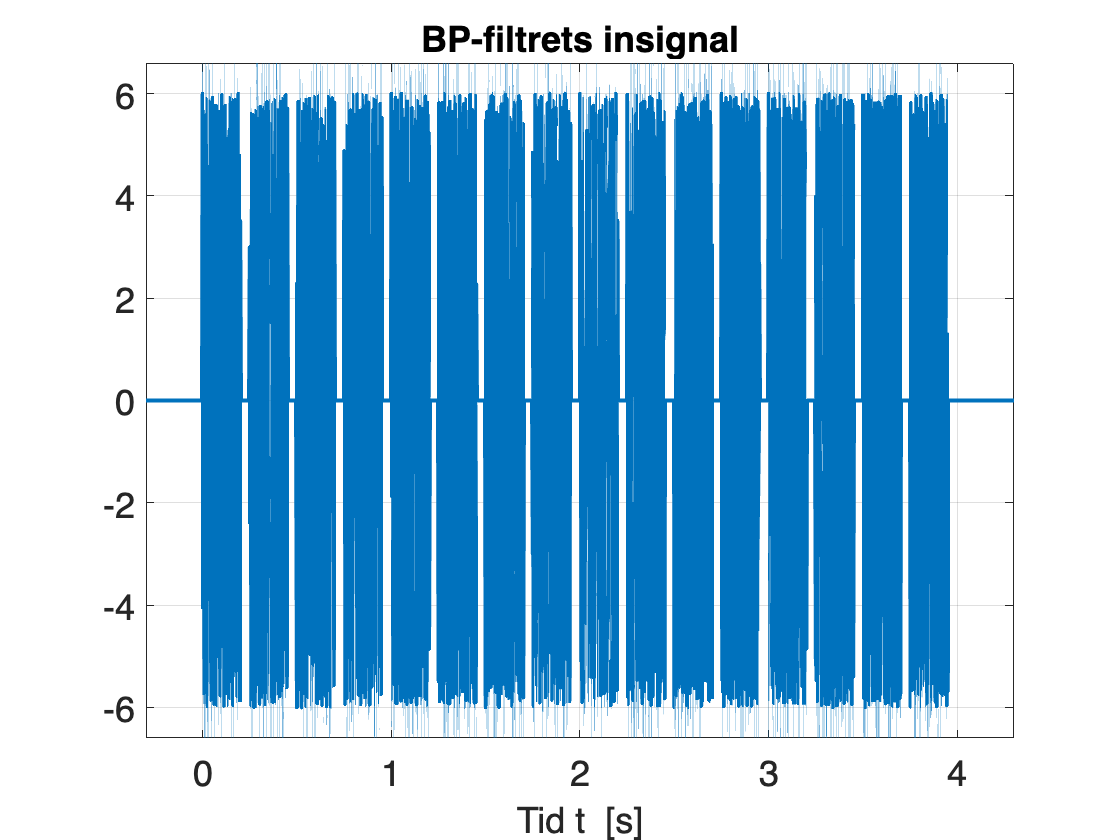

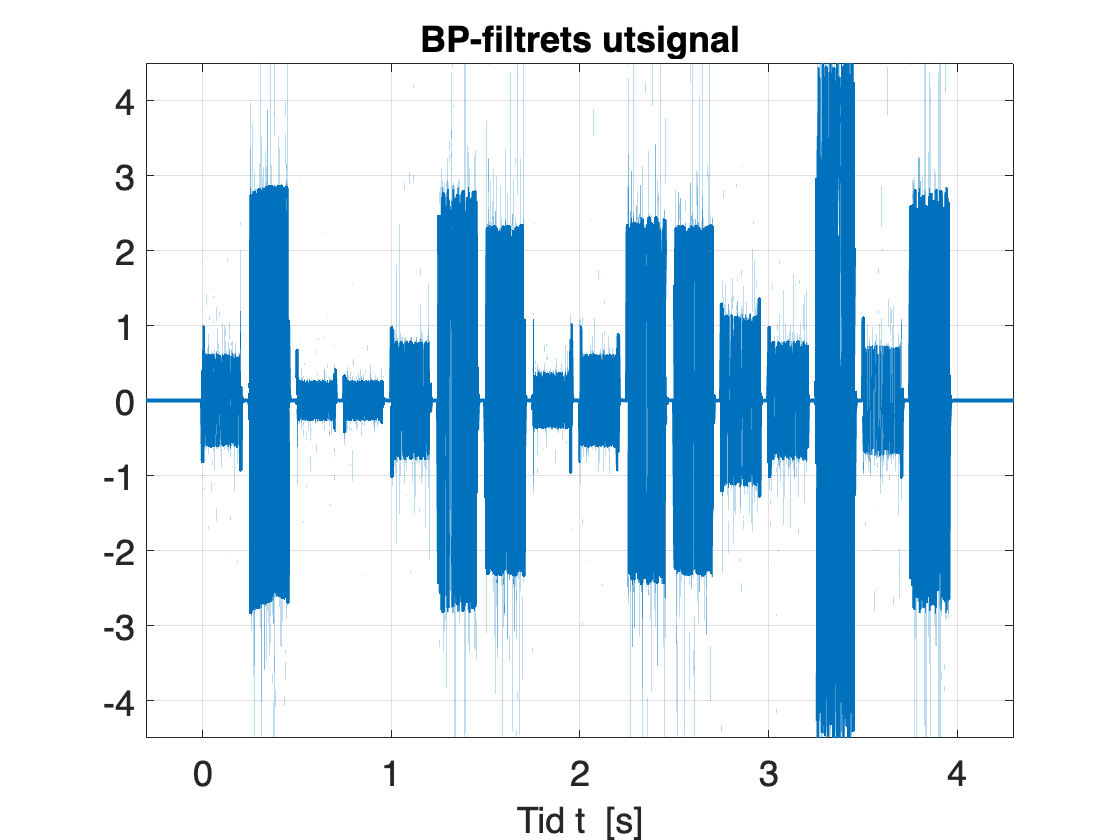

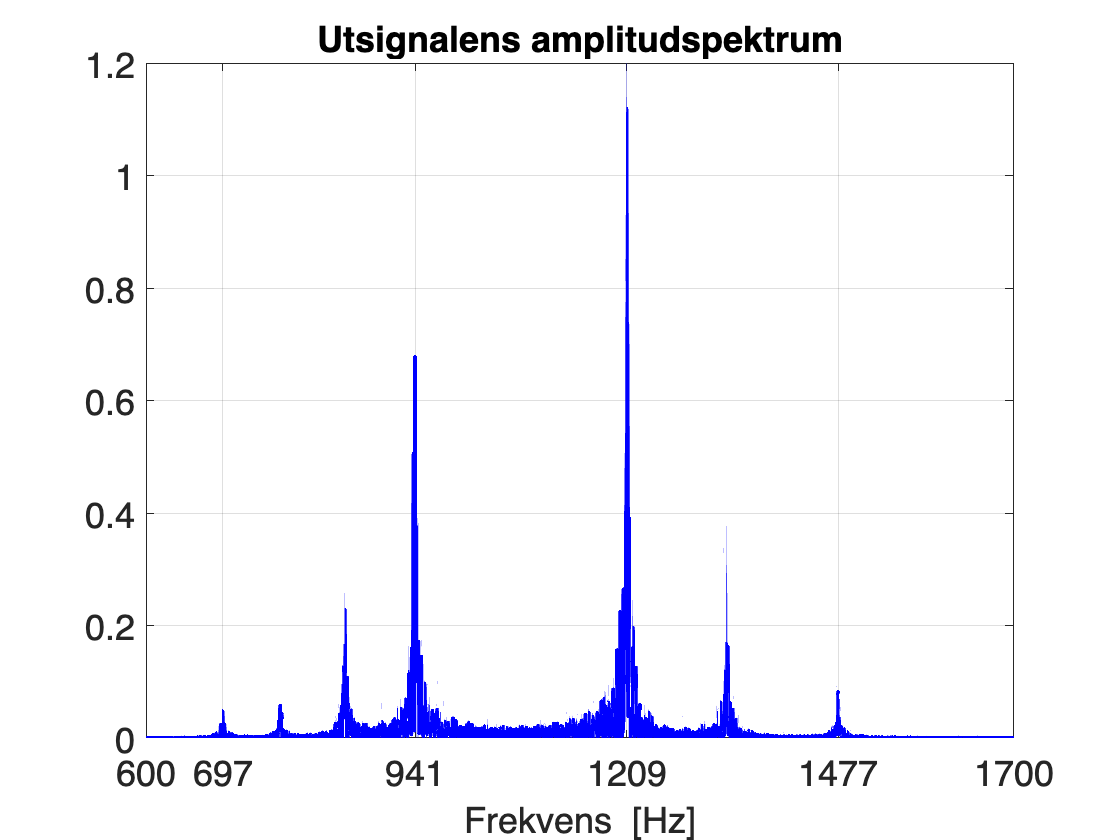

Utsignal = true;   % Rita BP-filtrets utsignal
UTSPEKTRUM = true; % Rita utsignalens amplitudspektrum
uppgift462

### Uppgift 4.6a

Vilka av knapptryckningarna i sekvensen innehåller någon/några av knapparna ”0”, ”1”, ”4”, ”7”, ”*”, ”#” eller ”D”?

Förklara hur du resonerar samt hur du tolkar utsignalens utseende, dvs. vilken information om knapptryckningarna som utsignalsgrafen ger dig.

Finns det någon kompletterande nyttig information om knapptryckningarna som utsignalens amplitudspektrum kan ge?

☆  **Knapptryckningar:**  Vi anser att tryck nummer 2, 6, 7, 10, 11, 14 och 16 innehåller någon av de angivna knapparna. 

☆  **Motivering:**  

Vi vet att alla insignaler som inte antar en amplitud på minst $\frac{1}{\sqrt{2}}*6$ ska filtreras bort. Vi ser då att det endast är tryck nummer 14 som kommer upp i denna nivå samt att resterande av de ovan angivna knapptryckningarna endast endast innehåller en av de "rätta frekvenserna". 

### Uppgift 4.6b

Är det någon eller några av dessa knapptryckningar som du med säkerhet kan säga är nedtryckt på en viss *plats* i sekvensen?

Vilken knapp och vilken plats i så fall? Förklara hur du resonerar!

☆  **Knapp:**  *

☆  **Motivering:**  

 Detta är tydligt då tryck nummer 14 är den signalen som kommer upp i rätt nivå samt att vid en närmare titt på utsignalens amplitudspektrum kan det konstateras att vi har tydliga spikar på 941 Hz och 1209 Hz, likt labb 2 motsvarar denna kombination av frekvenser en *. 

### Uppgift 4.6c

Vilka egenskaper/parametrar hos bandpassfiltret som kan förbättras/förändras om man vill uppnå ett ännu tydligare/bättre filtreringsresultat?

☆  **Svar:**  

Om vi hade fått höja filtrets ordning hade dämpningseffekten utanför det önskade bandet blivit bättre, vilket hade varit bra. I övrigt är vi osäkra. 

**Era lösta uppgifter i Laboration 3 ovan redovisas för assistenten under *****LABPASS 3*****, i enlighet med anvisningarna i introduktionen inför laboration 1. Laboration 1–2 ska vara redovisade innan Laboration 3 kan redovisas.**

**Det är lämpligt att ha med formelsamlingen vid redovisningstillfället, för att kunna relatera till samband och transformpar där.**

**Under tiden ni väntar på att det ska bli er grupps tur att redovisa, så fortsätt gärna att lösa uppgifter i nästa laboration.**